% Load results for scenario 5 random assign 
load('simulation_results_1_4.mat');% w1 = 0.7;  % Weight for reputation % w2 = 0.3;  % Weight for stay time
load('simulation_results_1_4_2.mat');% w1 = 0.3;  % Weight for reputation % w2 = 0.7;  % Weight for stay time
load('simulation_results_1_4_3.mat');% w1 = 0.5;  % Weight for reputation% w2 = 0.5;  % Weight for stay time
load('simulation_results_1_4_4.mat');%w1 = 1.0;  % Weight for reputation %w2 = 0.0;  % Weight for stay time
% Define the malicious percentages and success rate data
maliciousPercentages = 10:10:50;
% 1 Extract SuccessRates results for each scenario

dynamicSuccessRatesScenario1 = arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults_1_4);
dynamicSuccessRatesScenario2 = arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults_1_4_2);
dynamicSuccessRatesScenario3 = arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults_1_4_3);
dynamicSuccessRatesScenario4 = arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults_1_4_4);

fixedSuccessRatesScenario1 = arrayfun(@(x) x.Fixed.AvgSuccessRate, allResults_1_4);
fixedSuccessRatesScenario2 = arrayfun(@(x) x.Fixed.AvgSuccessRate, allResults_1_4_2);
fixedSuccessRatesScenario3 = arrayfun(@(x) x.Fixed.AvgSuccessRate, allResults_1_4_3);
fixedSuccessRatesScenario4 = arrayfun(@(x) x.Fixed.AvgSuccessRate, allResults_1_4_4);

% Plot both configurations on the same plot
figure;
hold on;

% Dynamic configuration
plot(maliciousPercentages, dynamicSuccessRatesScenario1, '-x', 'DisplayName', 'Dynamic - Scenario 1 (w1 = 0.7,w2 = 0.3)');
plot(maliciousPercentages, dynamicSuccessRatesScenario2, '-s', 'DisplayName', 'Dynamic - Scenario 1 (w1 = 0.3,w2 = 0.7)');
plot(maliciousPercentages, dynamicSuccessRatesScenario3, '-*', 'DisplayName', 'Dynamic - Scenario 1 (w1 = 0.5,w2 = 0.5)');
plot(maliciousPercentages, dynamicSuccessRatesScenario4, '-o', 'DisplayName', 'Dynamic - Scenario 1 (w1 = 1,w2 = 0)');


% Fixed configuration
plot(maliciousPercentages, fixedSuccessRatesScenario1, '--x', 'DisplayName', 'Fixed - Scenario 1 (w1 = 0.7,w2 = 0.3)');
plot(maliciousPercentages, fixedSuccessRatesScenario2, '--s', 'DisplayName', 'Fixed - Scenario 1 (w1 = 0.3,w2 = 0.7)');
plot(maliciousPercentages, fixedSuccessRatesScenario3, '--*', 'DisplayName', 'Fixed - Scenario 1 (w1 = 0.5,w2 = 0.5)');
plot(maliciousPercentages, fixedSuccessRatesScenario4, '--o', 'DisplayName', 'Fixed - Scenario 1 (w1 = 1,w2 = 0)');


% Labels, title, and legend
xlabel('Malicious Percentage (%)', 'FontSize', 12, 'FontName', 'Times');
ylabel('Success Rate', 'FontSize', 12, 'FontName', 'Times');
title({'Dynamic and Fixed Configuration: Success Rate Comparison ','for Scenario 5 in Different Weights(w1,w2)'}, 'FontSize', 14, 'FontName', 'Times');
legend('Location', 'best', 'FontSize', 10); % Legend outside the plot area

% Grid and limits
grid on;
xlim([10 50]); % Set x-axis limits
ylim auto; % Set y-axis limits (assuming success rate between 0 and 1)

% Set font sizes for axes
set(gca, 'FontSize', 10, 'FontName', 'Times');

% Adjust figure size and export settings
set(gcf, 'Position', [100, 100, 1000, 600]); % Adjust figure size for better visualization
set(gcf, 'PaperUnits', 'inches', 'PaperPosition', [0, 0, 6, 4]); % IEEE single-column layout

% Export the plot in high resolution
print(gcf, 'success_rate_comparison for Scenario 5 in Different Weights(w1,w2).pdf', '-dpdf', '-r300', '-bestfit'); % Save as PDF
print(gcf, 'success_rate_comparison for Scenario 5 in Different Weights(w1,w2).eps', '-depsc', '-r300'); % Save as EPS

%----------------------------------------------------%

% 2 Extract AvgLatency results for each scenario

dynamicAvgLatencyScenario1 = arrayfun(@(x) x.Dynamic.AvgLatency, allResults_1_4);
dynamicAvgLatencyScenario2 = arrayfun(@(x) x.Dynamic.AvgLatency, allResults_1_4_2);
dynamicAvgLatencyScenario3 = arrayfun(@(x) x.Dynamic.AvgLatency, allResults_1_4_3);
dynamicAvgLatencyScenario4 = arrayfun(@(x) x.Dynamic.AvgLatency, allResults_1_4_3);

fixedAvgLatencyScenario1 = arrayfun(@(x) x.Fixed.AvgLatency, allResults_1_4);
fixedAvgLatencyScenario2 = arrayfun(@(x) x.Fixed.AvgLatency, allResults_1_4_2);
fixedAvgLatencyScenario3 = arrayfun(@(x) x.Fixed.AvgLatency, allResults_1_4_3);
fixedAvgLatencyScenario4 = arrayfun(@(x) x.Fixed.AvgLatency, allResults_1_4_4);

% Plot both configurations on the same plot
figure;
hold on;

% Dynamic configuration
plot(maliciousPercentages, dynamicAvgLatencyScenario1, '-x', 'DisplayName', 'Dynamic - Scenario 1 (w1 = 0.7,w2 = 0.3)');
plot(maliciousPercentages, dynamicAvgLatencyScenario2, '-s', 'DisplayName', 'Dynamic - Scenario 1 (w1 = 0.3,w2 = 0.7)');
plot(maliciousPercentages, dynamicAvgLatencyScenario3, '-*', 'DisplayName', 'Dynamic - Scenario 1 (w1 = 0.5,w2 = 0.5)');
plot(maliciousPercentages, dynamicAvgLatencyScenario4, '-o', 'DisplayName', 'Dynamic - Scenario 1 (w1 = 1,w2 = 0)');


% Fixed configuration
plot(maliciousPercentages, fixedAvgLatencyScenario1, '--x', 'DisplayName', 'Fixed - Scenario 1 (w1 = 0.7,w2 = 0.3)');
plot(maliciousPercentages, fixedAvgLatencyScenario2, '--s', 'DisplayName', 'Fixed - Scenario 1 (w1 = 0.3,w2 = 0.7)');
plot(maliciousPercentages, fixedAvgLatencyScenario3, '--*', 'DisplayName', 'Fixed - Scenario 1 (w1 = 0.5,w2 = 0.5)');
plot(maliciousPercentages, fixedAvgLatencyScenario4, '--o', 'DisplayName', 'Fixed - Scenario 1 (w1 = 1,w2 = 0)');


% Labels, title, and legend
xlabel('Malicious Percentage (%)', 'FontSize', 12, 'FontName', 'Times');
ylabel('Avg Latency', 'FontSize', 12, 'FontName', 'Times');
title({'Dynamic and Fixed Configuration: Avg Latency Comparison', 'for Scenario 5 in Different Weights(w1,w2)'}, 'FontSize', 14, 'FontName', 'Times');
legend('Location', 'best', 'FontSize', 10); % Legend outside the plot area

% Grid and limits
grid on;
xlim([10 50]); % Set x-axis limits
ylim auto; % Set y-axis limits (assuming success rate between 0 and 1)

% Set font sizes for axes
set(gca, 'FontSize', 10, 'FontName', 'Times');

% Adjust figure size and export settings
set(gcf, 'Position', [100, 100, 1000, 600]); % Adjust figure size for better visualization
set(gcf, 'PaperUnits', 'inches', 'PaperPosition', [0, 0, 6, 4]); % IEEE single-column layout

% Export the plot in high resolution
print(gcf, 'AvgLatency_comparison for Scenario 5 in Different Weights(w1,w2).pdf', '-dpdf', '-r300', '-bestfit'); % Save as PDF
print(gcf, 'AvgLatency_comparison for Scenario 5 in Different Weights(w1,w2).eps', '-depsc', '-r300'); % Save as EPS
%----------------------------------------------------%

% 3 Extract AvgisMalicious results for each scenario

dynamicAvgisMaliciousScenario1 = arrayfun(@(x) x.Dynamic.AvgisMalicious, allResults_1_4);
dynamicAvgisMaliciousScenario2 = arrayfun(@(x) x.Dynamic.AvgisMalicious, allResults_1_4_2);
dynamicAvgisMaliciousScenario3 = arrayfun(@(x) x.Dynamic.AvgisMalicious, allResults_1_4_3);
dynamicAvgisMaliciousScenario4 = arrayfun(@(x) x.Dynamic.AvgisMalicious, allResults_1_4_4);

fixedAvgisMaliciousScenario1 = arrayfun(@(x) x.Fixed.AvgisMalicious, allResults_1_4);
fixedAvgisMaliciousScenario2 = arrayfun(@(x) x.Fixed.AvgisMalicious, allResults_1_4_2);
fixedAvgisMaliciousScenario3 = arrayfun(@(x) x.Fixed.AvgisMalicious, allResults_1_4_3);
fixedAvgisMaliciousScenario4 = arrayfun(@(x) x.Fixed.AvgisMalicious, allResults_1_4_4);

% Plot both configurations on the same plot
figure;
hold on;

% Dynamic configuration
plot(maliciousPercentages, dynamicAvgisMaliciousScenario1, '-x', 'DisplayName', 'Dynamic - Scenario 1 (w1 = 0.7,w2 = 0.3)');
plot(maliciousPercentages, dynamicAvgisMaliciousScenario2, '-s', 'DisplayName', 'Dynamic - Scenario 1 (w1 = 0.3,w2 = 0.7)');
plot(maliciousPercentages, dynamicAvgisMaliciousScenario3, '-*', 'DisplayName', 'Dynamic - Scenario 1 (w1 = 0.5,w2 = 0.5)');
plot(maliciousPercentages, dynamicAvgisMaliciousScenario4, '-o', 'DisplayName', 'Dynamic - Scenario 1 (w1 = 1,w2 = 0)');


% Fixed configuration
plot(maliciousPercentages, fixedAvgisMaliciousScenario1, '--x', 'DisplayName', 'Fixed - Scenario 1 (w1 = 0.7,w2 = 0.3)');
plot(maliciousPercentages, fixedAvgisMaliciousScenario2, '--s', 'DisplayName', 'Fixed - Scenario 1 (w1 = 0.3,w2 = 0.7)');
plot(maliciousPercentages, fixedAvgisMaliciousScenario3, '--*', 'DisplayName', 'Fixed - Scenario 1 (w1 = 0.5,w2 = 0.5)');
plot(maliciousPercentages, fixedAvgisMaliciousScenario4, '--o', 'DisplayName', 'Fixed - Scenario 1 (w1 = 1,w2 = 0)');


% Labels, title, and legend
xlabel('Malicious Percentage (%)', 'FontSize', 12, 'FontName', 'Times');
ylabel('Avg Selected Malicious Providers', 'FontSize', 12, 'FontName', 'Times');
title({'Dynamic and Fixed Configuration: Avgis Malicious Comparison', 'for Scenario 5 in Different Weights(w1,w2)'}, 'FontSize', 14, 'FontName', 'Times');
legend('Location', 'best', 'FontSize', 10); % Legend outside the plot area

% Grid and limits
grid on;
xlim([10 50]); % Set x-axis limits
ylim auto; % Set y-axis limits (assuming success rate between 0 and 1)

% Set font sizes for axes
set(gca, 'FontSize', 10, 'FontName', 'Times');

% Adjust figure size and export settings
set(gcf, 'Position', [100, 100, 1000, 600]); % Adjust figure size for better visualization
set(gcf, 'PaperUnits', 'inches', 'PaperPosition', [0, 0, 6, 4]); % IEEE single-column layout

% Export the plot in high resolution
print(gcf, 'AvgisMalicious_comparison for Scenario 5 in Different Weights(w1,w2).pdf', '-dpdf', '-r300', '-bestfit'); % Save as PDF
print(gcf, 'AvgisMalicious_comparison for Scenario 5 in Different Weights(w1,w2).eps', '-depsc', '-r300'); % Save as EPS
%----------------------------------------------------%
%4 calculate MAR
dynamicMaliciousAvoidanceRateScenario1 = 1 - dynamicAvgisMaliciousScenario1;
dynamicMaliciousAvoidanceRateScenario2 = 1 - dynamicAvgisMaliciousScenario2;
dynamicMaliciousAvoidanceRateScenario3 = 1 - dynamicAvgisMaliciousScenario3;
dynamicMaliciousAvoidanceRateScenario4 = 1 - dynamicAvgisMaliciousScenario4;


fixedMaliciousAvoidanceRateScenario1 = 1 - fixedAvgisMaliciousScenario1;
fixedMaliciousAvoidanceRateScenario2 = 1 - fixedAvgisMaliciousScenario2;
fixedMaliciousAvoidanceRateScenario3 = 1 - fixedAvgisMaliciousScenario3;
fixedMaliciousAvoidanceRateScenario4 = 1 - fixedAvgisMaliciousScenario4;


% Plot both configurations on the same plot
figure;
hold on;

% Dynamic configuration
plot(maliciousPercentages, dynamicMaliciousAvoidanceRateScenario1, '-x', 'DisplayName', 'Dynamic - Scenario 1 (w1 = 0.7,w2 = 0.3)');
plot(maliciousPercentages, dynamicMaliciousAvoidanceRateScenario2, '-s', 'DisplayName', 'Dynamic - Scenario 1 (w1 = 0.3,w2 = 0.7)');
plot(maliciousPercentages, dynamicMaliciousAvoidanceRateScenario3, '-*', 'DisplayName', 'Dynamic - Scenario 1 (w1 = 0.5,w2 = 0.5)');
plot(maliciousPercentages, dynamicMaliciousAvoidanceRateScenario4, '-o', 'DisplayName', 'Dynamic - Scenario 1 (w1 = 1,w2 = 0)');


% Fixed configuration
plot(maliciousPercentages, fixedMaliciousAvoidanceRateScenario1, '--x', 'DisplayName', 'Fixed - Scenario 1 (w1 = 0.7,w2 = 0.3)');
plot(maliciousPercentages, fixedMaliciousAvoidanceRateScenario2, '--s', 'DisplayName', 'Fixed - Scenario 1 (w1 = 0.3,w2 = 0.7)');
plot(maliciousPercentages, fixedMaliciousAvoidanceRateScenario3, '--*', 'DisplayName', 'Fixed - Scenario 1 (w1 = 0.5,w2 = 0.5)');
plot(maliciousPercentages, fixedMaliciousAvoidanceRateScenario4, '--o', 'DisplayName', 'Fixed - Scenario 1 (w1 = 1,w2 = 0)');


% Labels, title, and legend
xlabel('Malicious Percentage (%)', 'FontSize', 12, 'FontName', 'Times');
ylabel('MAR', 'FontSize', 12, 'FontName', 'Times');
title({'Dynamic and Fixed Configuration: Malicious Avoidance Rate (MAR) Comparison',' for Scenario 5 in Different Weights(w1,w2)'}, 'FontSize', 14, 'FontName', 'Times');
legend('Location', 'best', 'FontSize', 10); % Legend outside the plot area

% Grid and limits
grid on;
xlim([10 50]); % Set x-axis limits
ylim auto; % Set y-axis limits (assuming success rate between 0 and 1)

% Set font sizes for axes
set(gca, 'FontSize', 10, 'FontName', 'Times');

% Adjust figure size and export settings
set(gcf, 'Position', [100, 100, 1000, 600]); % Adjust figure size for better visualization
set(gcf, 'PaperUnits', 'inches', 'PaperPosition', [0, 0, 6, 4]); % IEEE single-column layout

% Export the plot in high resolution
print(gcf, 'MAR_comparison for Scenario 5 in Different Weights(w1,w2).pdf', '-dpdf', '-r300', '-bestfit'); % Save as PDF
print(gcf, 'MAR_comparison for Scenario 5 in Different Weights(w1,w2).eps', '-depsc', '-r300'); % Save as EPS
%----------------------------------------------------%

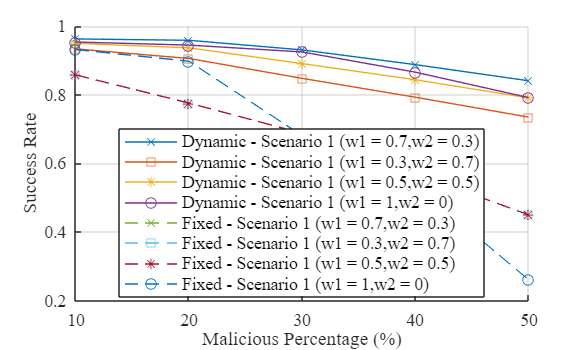

% Load results for the three scenarios
load('simulation_results_1_3.mat');% w1 = 0.7;  % Weight for reputation % w2 = 0.3;  % Weight for stay time
load('simulation_results_1_3_2.mat');% w1 = 0.3;  % Weight for reputation % w2 = 0.7;  % Weight for stay time
load('simulation_results_1_3_3.mat');% w1 = 0.5;  % Weight for reputation% w2 = 0.5;  % Weight for stay time
load('simulation_results_1_3_4.mat');%w1 = 1.0;  % Weight for reputation %w2 = 0.0;  % Weight for stay time
% Define the malicious percentages and success rate data
maliciousPercentages = 10:10:50;
% 1 Extract SuccessRates results for each scenario

dynamicSuccessRatesScenario1 = arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults_1_3);
dynamicSuccessRatesScenario2 = arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults_1_3_2);
dynamicSuccessRatesScenario3 = arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults_1_3_3);
dynamicSuccessRatesScenario4 = arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults_1_3_4);

fixedSuccessRatesScenario1 = arrayfun(@(x) x.Fixed.AvgSuccessRate, allResults_1_3);
fixedSuccessRatesScenario2 = arrayfun(@(x) x.Fixed.AvgSuccessRate, allResults_1_3_2);
fixedSuccessRatesScenario3 = arrayfun(@(x) x.Fixed.AvgSuccessRate, allResults_1_3_3);
fixedSuccessRatesScenario4 = arrayfun(@(x) x.Fixed.AvgSuccessRate, allResults_1_3_4);

% Plot both configurations on the same plot
figure;
hold on;

% Dynamic configuration
plot(maliciousPercentages, dynamicSuccessRatesScenario1, '-x', 'DisplayName', 'Dynamic - Scenario 1 (w1 = 0.7,w2 = 0.3)');
plot(maliciousPercentages, dynamicSuccessRatesScenario2, '-s', 'DisplayName', 'Dynamic - Scenario 1 (w1 = 0.3,w2 = 0.7)');
plot(maliciousPercentages, dynamicSuccessRatesScenario3, '-*', 'DisplayName', 'Dynamic - Scenario 1 (w1 = 0.5,w2 = 0.5)');
plot(maliciousPercentages, dynamicSuccessRatesScenario4, '-o', 'DisplayName', 'Dynamic - Scenario 1 (w1 = 1,w2 = 0)');


% Fixed configuration
plot(maliciousPercentages, fixedSuccessRatesScenario1, '--x', 'DisplayName', 'Fixed - Scenario 1 (w1 = 0.7,w2 = 0.3)');
plot(maliciousPercentages, fixedSuccessRatesScenario2, '--s', 'DisplayName', 'Fixed - Scenario 1 (w1 = 0.3,w2 = 0.7)');
plot(maliciousPercentages, fixedSuccessRatesScenario3, '--*', 'DisplayName', 'Fixed - Scenario 1 (w1 = 0.5,w2 = 0.5)');
plot(maliciousPercentages, fixedSuccessRatesScenario4, '--o', 'DisplayName', 'Fixed - Scenario 1 (w1 = 1,w2 = 0)');


% Labels, title, and legend
xlabel('Malicious Percentage (%)', 'FontSize', 12, 'FontName', 'Times');
ylabel('Success Rate', 'FontSize', 12, 'FontName', 'Times');
%title({'Dynamic and Fixed Configuration: Success Rate Comparison ','for Scenario 1 in Different Weights(w1,w2)'}, 'FontSize', 14, 'FontName', 'Times');
legend('Location', 'best', 'FontSize', 10); % Legend outside the plot area

% Grid and limits
grid on;
xlim([10 50]); % Set x-axis limits
ylim auto; % Set y-axis limits (assuming success rate between 0 and 1)

% Set font sizes for axes
set(gca, 'FontSize', 10, 'FontName', 'Times');

% Adjust figure size and export settings
set(gcf, 'Position', [100, 100, 1000, 600]); % Adjust figure size for better visualization
set(gcf, 'PaperUnits', 'inches', 'PaperPosition', [0, 0, 6, 4]); % IEEE single-column layout

% Export the plot in high resolution
print(gcf, 'success_rate_comparison for Scenario 1 in Different Weights(w1,w2).pdf', '-dpdf', '-r300', '-bestfit'); % Save as PDF
print(gcf, 'success_rate_comparison for Scenario 1 in Different Weights(w1,w2).eps', '-depsc', '-r300'); % Save as EPS
export_fig('success_rate_comparison for Scenario 1 in Different Weights(w1,w2).pdf', '-pdf', '-transparent', '-painters');

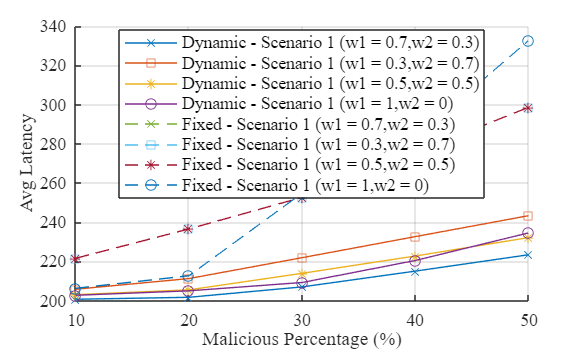

%----------------------------------------------------%

% 2 Extract AvgLatency results for each scenario

dynamicAvgLatencyScenario1 = arrayfun(@(x) x.Dynamic.AvgLatency, allResults_1_3);
dynamicAvgLatencyScenario2 = arrayfun(@(x) x.Dynamic.AvgLatency, allResults_1_3_2);
dynamicAvgLatencyScenario3 = arrayfun(@(x) x.Dynamic.AvgLatency, allResults_1_3_3);
dynamicAvgLatencyScenario4 = arrayfun(@(x) x.Dynamic.AvgLatency, allResults_1_3_4);

fixedAvgLatencyScenario1 = arrayfun(@(x) x.Fixed.AvgLatency, allResults_1_3);
fixedAvgLatencyScenario2 = arrayfun(@(x) x.Fixed.AvgLatency, allResults_1_3_2);
fixedAvgLatencyScenario3 = arrayfun(@(x) x.Fixed.AvgLatency, allResults_1_3_3);
fixedAvgLatencyScenario4 = arrayfun(@(x) x.Fixed.AvgLatency, allResults_1_3_4);

% Plot both configurations on the same plot
figure;
hold on;

% Dynamic configuration
plot(maliciousPercentages, dynamicAvgLatencyScenario1, '-x', 'DisplayName', 'Dynamic - Scenario 1 (w1 = 0.7,w2 = 0.3)');
plot(maliciousPercentages, dynamicAvgLatencyScenario2, '-s', 'DisplayName', 'Dynamic - Scenario 1 (w1 = 0.3,w2 = 0.7)');
plot(maliciousPercentages, dynamicAvgLatencyScenario3, '-*', 'DisplayName', 'Dynamic - Scenario 1 (w1 = 0.5,w2 = 0.5)');
plot(maliciousPercentages, dynamicAvgLatencyScenario4, '-o', 'DisplayName', 'Dynamic - Scenario 1 (w1 = 1,w2 = 0)');


% Fixed configuration
plot(maliciousPercentages, fixedAvgLatencyScenario1, '--x', 'DisplayName', 'Fixed - Scenario 1 (w1 = 0.7,w2 = 0.3)');
plot(maliciousPercentages, fixedAvgLatencyScenario2, '--s', 'DisplayName', 'Fixed - Scenario 1 (w1 = 0.3,w2 = 0.7)');
plot(maliciousPercentages, fixedAvgLatencyScenario3, '--*', 'DisplayName', 'Fixed - Scenario 1 (w1 = 0.5,w2 = 0.5)');
plot(maliciousPercentages, fixedAvgLatencyScenario4, '--o', 'DisplayName', 'Fixed - Scenario 1 (w1 = 1,w2 = 0)');


% Labels, title, and legend
xlabel('Malicious Percentage (%)', 'FontSize', 12, 'FontName', 'Times');
ylabel('Avg Latency', 'FontSize', 12, 'FontName', 'Times');
%title({'Dynamic and Fixed Configuration: Avg Latency Comparison', 'for Scenario 1 in Different Weights(w1,w2)'}, 'FontSize', 14, 'FontName', 'Times');
legend('Location', 'best', 'FontSize', 10); % Legend outside the plot area

% Grid and limits
grid on;
xlim([10 50]); % Set x-axis limits
ylim auto; % Set y-axis limits (assuming success rate between 0 and 1)

% Set font sizes for axes
set(gca, 'FontSize', 10, 'FontName', 'Times');

% Adjust figure size and export settings
set(gcf, 'Position', [100, 100, 1000, 600]); % Adjust figure size for better visualization
set(gcf, 'PaperUnits', 'inches', 'PaperPosition', [0, 0, 6, 4]); % IEEE single-column layout

% Export the plot in high resolution
print(gcf, 'AvgLatency_comparison for Scenario 1 in Different Weights(w1,w2).pdf', '-dpdf', '-r300', '-bestfit'); % Save as PDF
print(gcf, 'AvgLatency_comparison for Scenario 1 in Different Weights(w1,w2).eps', '-depsc', '-r300'); % Save as EPS
export_fig('AvgLatency_comparison for Scenario 1 in Different Weights(w1,w2).pdf', '-pdf', '-transparent', '-painters');

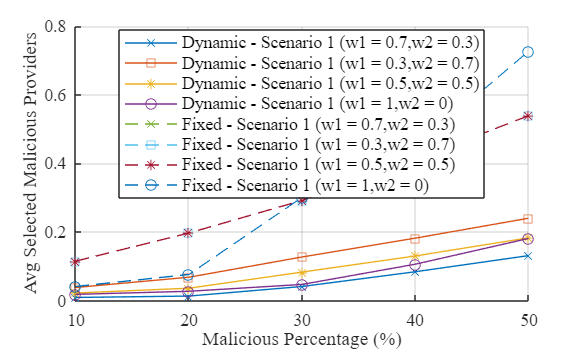

%----------------------------------------------------%

% 3 Extract AvgisMalicious results for each scenario

dynamicAvgisMaliciousScenario1 = arrayfun(@(x) x.Dynamic.AvgisMalicious, allResults_1_3);
dynamicAvgisMaliciousScenario2 = arrayfun(@(x) x.Dynamic.AvgisMalicious, allResults_1_3_2);
dynamicAvgisMaliciousScenario3 = arrayfun(@(x) x.Dynamic.AvgisMalicious, allResults_1_3_3);
dynamicAvgisMaliciousScenario4 = arrayfun(@(x) x.Dynamic.AvgisMalicious, allResults_1_3_4);

fixedAvgisMaliciousScenario1 = arrayfun(@(x) x.Fixed.AvgisMalicious, allResults_1_3);
fixedAvgisMaliciousScenario2 = arrayfun(@(x) x.Fixed.AvgisMalicious, allResults_1_3_2);
fixedAvgisMaliciousScenario3 = arrayfun(@(x) x.Fixed.AvgisMalicious, allResults_1_3_3);
fixedAvgisMaliciousScenario4 = arrayfun(@(x) x.Fixed.AvgisMalicious, allResults_1_3_4);

% Plot both configurations on the same plot
figure;
hold on;

% Dynamic configuration
plot(maliciousPercentages, dynamicAvgisMaliciousScenario1, '-x', 'DisplayName', 'Dynamic - Scenario 1 (w1 = 0.7,w2 = 0.3)');
plot(maliciousPercentages, dynamicAvgisMaliciousScenario2, '-s', 'DisplayName', 'Dynamic - Scenario 1 (w1 = 0.3,w2 = 0.7)');
plot(maliciousPercentages, dynamicAvgisMaliciousScenario3, '-*', 'DisplayName', 'Dynamic - Scenario 1 (w1 = 0.5,w2 = 0.5)');
plot(maliciousPercentages, dynamicAvgisMaliciousScenario4, '-o', 'DisplayName', 'Dynamic - Scenario 1 (w1 = 1,w2 = 0)');


% Fixed configuration
plot(maliciousPercentages, fixedAvgisMaliciousScenario1, '--x', 'DisplayName', 'Fixed - Scenario 1 (w1 = 0.7,w2 = 0.3)');
plot(maliciousPercentages, fixedAvgisMaliciousScenario2, '--s', 'DisplayName', 'Fixed - Scenario 1 (w1 = 0.3,w2 = 0.7)');
plot(maliciousPercentages, fixedAvgisMaliciousScenario3, '--*', 'DisplayName', 'Fixed - Scenario 1 (w1 = 0.5,w2 = 0.5)');
plot(maliciousPercentages, fixedAvgisMaliciousScenario4, '--o', 'DisplayName', 'Fixed - Scenario 1 (w1 = 1,w2 = 0)');


% Labels, title, and legend
xlabel('Malicious Percentage (%)', 'FontSize', 12, 'FontName', 'Times');
ylabel('Avg Selected Malicious Providers', 'FontSize', 12, 'FontName', 'Times');
%title({'Dynamic and Fixed Configuration: Avgis Malicious Comparison', 'for Scenario 1 in Different Weights(w1,w2)'}, 'FontSize', 14, 'FontName', 'Times');
legend('Location', 'best', 'FontSize', 10); % Legend outside the plot area

% Grid and limits
grid on;
xlim([10 50]); % Set x-axis limits
ylim auto; % Set y-axis limits (assuming success rate between 0 and 1)

% Set font sizes for axes
set(gca, 'FontSize', 10, 'FontName', 'Times');

% Adjust figure size and export settings
set(gcf, 'Position', [100, 100, 1000, 600]); % Adjust figure size for better visualization
set(gcf, 'PaperUnits', 'inches', 'PaperPosition', [0, 0, 6, 4]); % IEEE single-column layout

% Export the plot in high resolution
print(gcf, 'AvgisMalicious_comparison for Scenario 1 in Different Weights(w1,w2).pdf', '-dpdf', '-r300', '-bestfit'); % Save as PDF
print(gcf, 'AvgisMalicious_comparison for Scenario 1 in Different Weights(w1,w2).eps', '-depsc', '-r300'); % Save as EPS
export_fig('AvgisMalicious_comparison for Scenario 1 in Different Weights(w1,w2).pdf', '-pdf', '-transparent', '-painters');

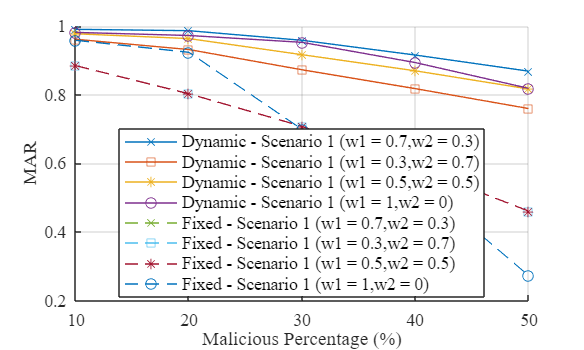

%----------------------------------------------------%
%4 calculate MAR
dynamicMaliciousAvoidanceRateScenario1 = 1 - dynamicAvgisMaliciousScenario1;
dynamicMaliciousAvoidanceRateScenario2 = 1 - dynamicAvgisMaliciousScenario2;
dynamicMaliciousAvoidanceRateScenario3 = 1 - dynamicAvgisMaliciousScenario3;
dynamicMaliciousAvoidanceRateScenario4 = 1 - dynamicAvgisMaliciousScenario4;


fixedMaliciousAvoidanceRateScenario1 = 1 - fixedAvgisMaliciousScenario1;
fixedMaliciousAvoidanceRateScenario2 = 1 - fixedAvgisMaliciousScenario2;
fixedMaliciousAvoidanceRateScenario3 = 1 - fixedAvgisMaliciousScenario3;
fixedMaliciousAvoidanceRateScenario4 = 1 - fixedAvgisMaliciousScenario4;


% Plot both configurations on the same plot
figure;
hold on;

% Dynamic configuration
plot(maliciousPercentages, dynamicMaliciousAvoidanceRateScenario1, '-x', 'DisplayName', 'Dynamic - Scenario 1 (w1 = 0.7,w2 = 0.3)');
plot(maliciousPercentages, dynamicMaliciousAvoidanceRateScenario2, '-s', 'DisplayName', 'Dynamic - Scenario 1 (w1 = 0.3,w2 = 0.7)');
plot(maliciousPercentages, dynamicMaliciousAvoidanceRateScenario3, '-*', 'DisplayName', 'Dynamic - Scenario 1 (w1 = 0.5,w2 = 0.5)');
plot(maliciousPercentages, dynamicMaliciousAvoidanceRateScenario4, '-o', 'DisplayName', 'Dynamic - Scenario 1 (w1 = 1,w2 = 0)');


% Fixed configuration
plot(maliciousPercentages, fixedMaliciousAvoidanceRateScenario1, '--x', 'DisplayName', 'Fixed - Scenario 1 (w1 = 0.7,w2 = 0.3)');
plot(maliciousPercentages, fixedMaliciousAvoidanceRateScenario2, '--s', 'DisplayName', 'Fixed - Scenario 1 (w1 = 0.3,w2 = 0.7)');
plot(maliciousPercentages, fixedMaliciousAvoidanceRateScenario3, '--*', 'DisplayName', 'Fixed - Scenario 1 (w1 = 0.5,w2 = 0.5)');
plot(maliciousPercentages, fixedMaliciousAvoidanceRateScenario4, '--o', 'DisplayName', 'Fixed - Scenario 1 (w1 = 1,w2 = 0)');


% Labels, title, and legend
xlabel('Malicious Percentage (%)', 'FontSize', 12, 'FontName', 'Times');
ylabel('MAR', 'FontSize', 12, 'FontName', 'Times');
%title({'Dynamic and Fixed Configuration: Malicious Avoidance Rate (MAR) Comparison',' for Scenario 1 in Different Weights(w1,w2)'}, 'FontSize', 14, 'FontName', 'Times');
legend('Location', 'best', 'FontSize', 10); % Legend outside the plot area

% Grid and limits
grid on;
xlim([10 50]); % Set x-axis limits
ylim auto; % Set y-axis limits (assuming success rate between 0 and 1)

% Set font sizes for axes
set(gca, 'FontSize', 10, 'FontName', 'Times');

% Adjust figure size and export settings
set(gcf, 'Position', [100, 100, 1000, 600]); % Adjust figure size for better visualization
set(gcf, 'PaperUnits', 'inches', 'PaperPosition', [0, 0, 6, 4]); % IEEE single-column layout

% Export the plot in high resolution
print(gcf, 'MAR_comparison for Scenario 1 in Different Weights(w1,w2).pdf', '-dpdf', '-r300', '-bestfit'); % Save as PDF
print(gcf, 'MAR_comparison for Scenario 1 in Different Weights(w1,w2).eps', '-depsc', '-r300'); % Save as EPS
export_fig('MAR_comparison for Scenario 1 in Different Weights(w1,w2).pdf', '-pdf', '-transparent', '-painters');

%----------------------------------------------------%

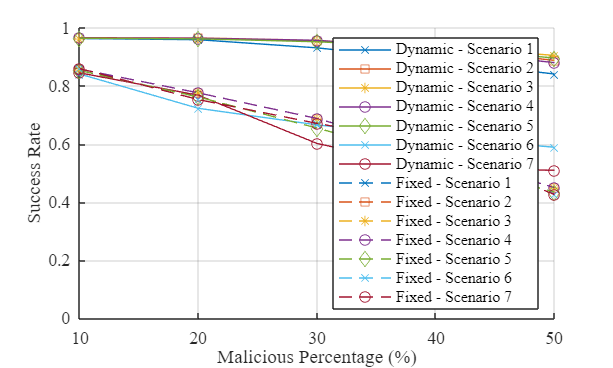

%legend inside
% Load results for the three scenarios
load('simulation_results_1_3.mat');
load('simulation_results_1_2.mat');% random selection skewed high
load('simulation_results_2_2.mat');
load('simulation_results_6_2.mat');%random selection balanced
load('simulation_results_4_2.mat')%random assign
load('simulation_results_5_2.mat')
load('simulation_results_6_3.mat')%scenario6 balanced 
%----------------------------------------------------%
% Define the malicious percentages and success rate data
maliciousPercentages = 10:10:50;
% Extract SuccessRates results for each scenario

dynamicSuccessRatesScenario1 = arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults_1_3);
dynamicSuccessRatesScenario2 = arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults_2_2);
dynamicSuccessRatesScenario3 = arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults_6_2);
dynamicSuccessRatesScenario4 = arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults_4_2);
dynamicSuccessRatesScenario5 = arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults_5_2);
dynamicSuccessRatesScenario6 = arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults_6_3);
dynamicSuccessRatesScenario7 = arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults_1_2);

fixedSuccessRatesScenario1 = arrayfun(@(x) x.Fixed.AvgSuccessRate, allResults_1_3);
fixedSuccessRatesScenario2 = arrayfun(@(x) x.Fixed.AvgSuccessRate, allResults_2_2);
fixedSuccessRatesScenario3 = arrayfun(@(x) x.Fixed.AvgSuccessRate, allResults_6_2);
fixedSuccessRatesScenario4 = arrayfun(@(x) x.Fixed.AvgSuccessRate, allResults_4_2);
fixedSuccessRatesScenario5 = arrayfun(@(x) x.Fixed.AvgSuccessRate, allResults_5_2);
fixedSuccessRatesScenario6 = arrayfun(@(x) x.Fixed.AvgSuccessRate, allResults_6_3);
fixedSuccessRatesScenario7 = arrayfun(@(x) x.Fixed.AvgSuccessRate, allResults_1_2);

% % Extract SuccessRates results for each scenario (Dynamic )
% dynamicSuccessRates_fixed = [
%     arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults_1_3);
%     arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults_2_2);
%     arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults_4_2);
%     arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults_5_2);
%     arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults_6_3)
% 
% ];


% % Extract SuccessRates results for each scenario (Fixed)
% fixedSuccessRates_fixed = [
%     arrayfun(@(x) x.Fixed.AvgSuccessRate, allResults_1_3);
%     arrayfun(@(x) x.Fixed.AvgSuccessRate, allResults_2_2);
%     arrayfun(@(x) x.Fixed.AvgSuccessRate, allResults_4_2);
%     arrayfun(@(x) x.Fixed.AvgSuccessRate, allResults_5_2);
%     arrayfun(@(x) x.Fixed.AvgSuccessRate, allResults_6_3)
% 
% ];
% 
% % Extract SuccessRates results for each scenario (Dynamic and random selection )
% dynamicSuccessRates_Random= [
%     arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults_1_2);
%     arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults_6_2)
% 
% ];

% % Calculate average success rates for Dynamic and Fixed
% avgDynamicSuccessRate = mean(mean(dynamicSuccessRates_fixed));
% avgFixedSuccessRate = mean(mean(fixedSuccessRates_fixed));
% avgRandomSuccessRate = mean(mean(dynamicSuccessRates_Random));

% Plot both configurations on the same plot
figure;
hold on;

% Dynamic configuration
plot(maliciousPercentages, dynamicSuccessRatesScenario1, '-x', 'DisplayName', 'Dynamic - Scenario 1');
plot(maliciousPercentages, dynamicSuccessRatesScenario2, '-s', 'DisplayName', 'Dynamic - Scenario 2');
plot(maliciousPercentages, dynamicSuccessRatesScenario5, '-*', 'DisplayName', 'Dynamic - Scenario 3');
plot(maliciousPercentages, dynamicSuccessRatesScenario6, '-o', 'DisplayName', 'Dynamic - Scenario 4');
plot(maliciousPercentages, dynamicSuccessRatesScenario4, '-d', 'DisplayName', 'Dynamic - Scenario 5');
plot(maliciousPercentages, dynamicSuccessRatesScenario7, '-x', 'DisplayName', 'Dynamic - Scenario 6');
plot(maliciousPercentages, dynamicSuccessRatesScenario3, '-o', 'DisplayName', 'Dynamic - Scenario 7');

% Fixed configuration
plot(maliciousPercentages, fixedSuccessRatesScenario1, '--x', 'DisplayName', 'Fixed - Scenario 1');
plot(maliciousPercentages, fixedSuccessRatesScenario2, '--s', 'DisplayName', 'Fixed - Scenario 2');
plot(maliciousPercentages, fixedSuccessRatesScenario5, '--*', 'DisplayName', 'Fixed - Scenario 3');
plot(maliciousPercentages, fixedSuccessRatesScenario6, '--o', 'DisplayName', 'Fixed - Scenario 4');
plot(maliciousPercentages, fixedSuccessRatesScenario4, '--d', 'DisplayName', 'Fixed - Scenario 5');
plot(maliciousPercentages, fixedSuccessRatesScenario7, '--x', 'DisplayName', 'Fixed - Scenario 6');
plot(maliciousPercentages, fixedSuccessRatesScenario3, '--o', 'DisplayName', 'Fixed - Scenario 7');

% % Add average success rates as horizontal lines with distinct colors
% yline(avgDynamicSuccessRate, '-b', 'LineWidth', 1.5, 'DisplayName', 'Avg Dynamic Success Rate') % Blue
% yline(avgFixedSuccessRate, '--r', 'LineWidth', 1.5, 'DisplayName', 'Avg Fixed Success Rate') % Red
% yline(avgRandomSuccessRate, '-.g', 'LineWidth', 1.5, 'DisplayName', 'Avg Random Success Rate')% Green

% % Annotate average improvement
% improvement = ((avgDynamicSuccessRate - avgFixedSuccessRate) / avgFixedSuccessRate) * 100;
% annotation('textbox', [0.15, 0.8, 0.1, 0.1], 'String', ...
%     sprintf('Avg Improvement: %.2f%%', improvement), 'FontSize', 12, 'BackgroundColor', 'white');
% % Annotate average improvement
% improvement2 = ((avgDynamicSuccessRate - avgRandomSuccessRate) / avgRandomSuccessRate) * 100;
% annotation('textbox', [0.15, 0.8, 0.1, 0.1], 'String', ...
%     sprintf('Avg Improvement: %.2f%%', improvement2), 'FontSize', 12, 'BackgroundColor', 'white');

% Labels, title, and legend
xlabel('Malicious Percentage (%)', 'FontSize', 12, 'FontName', 'Times');
ylabel('Success Rate', 'FontSize', 12, 'FontName', 'Times');
%title('Dynamic and Fixed Configuration: Success Rate Comparison', 'FontSize', 14, 'FontName', 'Times');
legend('Location', 'best');

% Grid and limits
grid on;
xlim([10 50]); % Set x-axis limits
ylim([0 1]); % Set y-axis limits (assuming success rate between 0 and 1)

% Set font sizes for axes
set(gca, 'FontSize', 10, 'FontName', 'Times');

% Adjust figure size and export settings
set(gcf, 'Position', [100, 100, 1000, 600]); % Adjust figure size for better visualization
set(gcf, 'PaperUnits', 'inches', 'PaperPosition', [0, 0, 6, 4]); % IEEE single-column layout

% Export the plot in high resolution
print(gcf, 'success_rate_comparison.pdf', '-dpdf', '-r300', '-bestfit'); % Save as PDF
print(gcf, 'success_rate_comparison.eps', '-depsc', '-r300'); % Save as EPS
export_fig('success_rate_comparison.pdf', '-pdf', '-transparent', '-painters');


%----------------------------------------------------%


% Load results for the three scenarios
load('simulation_results_1_3.mat');
load('simulation_results_1_2.mat'); % random selection skewed high
load('simulation_results_2_2.mat');
load('simulation_results_6_2.mat'); % random selection balanced
load('simulation_results_4_2.mat'); % random assign
load('simulation_results_5_2.mat');
load('simulation_results_6_3.mat'); % scenario6 balanced 

% Define the malicious percentages and success rate data
maliciousPercentages = 10:10:50;

% Extract SuccessRates results for each scenario (Dynamic )
dynamicSuccessRates_fixed = [
    arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults_1_3);
    arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults_2_2);
    arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults_4_2);
    arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults_5_2);
    arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults_6_3)
    
];


% Extract SuccessRates results for each scenario (Fixed)
fixedSuccessRates_fixed = [
    arrayfun(@(x) x.Fixed.AvgSuccessRate, allResults_1_3);
    arrayfun(@(x) x.Fixed.AvgSuccessRate, allResults_2_2);
    arrayfun(@(x) x.Fixed.AvgSuccessRate, allResults_4_2);
    arrayfun(@(x) x.Fixed.AvgSuccessRate, allResults_5_2);
    arrayfun(@(x) x.Fixed.AvgSuccessRate, allResults_6_3)
    
];

% Extract SuccessRates results for each scenario (Dynamic and random selection )
dynamicSuccessRates_Random= [
    arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults_1_2);
    arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults_6_2)
    
];

% Calculate average success rates for Dynamic and Fixed
avgDynamicSuccessRate = mean(mean(dynamicSuccessRates_fixed));
avgFixedSuccessRate = mean(mean(fixedSuccessRates_fixed));
avgRandomSuccessRate = mean(mean(dynamicSuccessRates_Random));

% Plot both configurations on the same plot
figure;
hold on;

% Dynamic configuration (individual scenarios)
plot(maliciousPercentages, dynamicSuccessRates_fixed, '-o', 'DisplayName', 'Dynamic Scenarios');

% Fixed configuration (individual scenarios)
plot(maliciousPercentages, fixedSuccessRates_fixed, '--x', 'DisplayName', 'Fixed Scenarios');

% Add average success rates as horizontal lines
yline(avgDynamicSuccessRate, '-k', 'LineWidth', 1.5, 'DisplayName', 'Avg Dynamic Success Rate');
yline(avgFixedSuccessRate, '--k', 'LineWidth', 1.5, 'DisplayName', 'Avg Fixed Success Rate');
yline(avgRandomSuccessRate, '--k', 'LineWidth', 1.5, 'DisplayName', 'Avg Random Success Rate');

% Annotate average improvement
improvement = ((avgDynamicSuccessRate - avgFixedSuccessRate) / avgFixedSuccessRate) * 100;
annotation('textbox', [0.15, 0.8, 0.1, 0.1], 'String', ...
    sprintf('Avg Improvement: %.2f%%', improvement), 'FontSize', 12, 'BackgroundColor', 'white');

% Labels, title, and legend
xlabel('Malicious Percentage (%)', 'FontSize', 12, 'FontName', 'Times');
ylabel('Success Rate', 'FontSize', 12, 'FontName', 'Times');
title('Dynamic and Fixed Configuration: Success Rate Comparison', 'FontSize', 14, 'FontName', 'Times');
legend('Location', 'best');

% Grid and limits
grid on;
xlim([10 50]); % Set x-axis limits
ylim([0 1]); % Set y-axis limits (assuming success rate between 0 and 1)

% Set font sizes for axes
set(gca, 'FontSize', 10, 'FontName', 'Times');

% Adjust figure size and export settings
set(gcf, 'Position', [100, 100, 1000, 600]); % Adjust figure size for better visualization
set(gcf, 'PaperUnits', 'inches', 'PaperPosition', [0, 0, 6, 4]); % IEEE single-column layout

% Export the plot in high resolution
print(gcf, 'success_rate_comparison_with_avg.pdf', '-dpdf', '-r300', '-bestfit'); % Save as PDF
print(gcf, 'success_rate_comparison_with_avg.eps', '-depsc', '-r300'); % Save as EPS


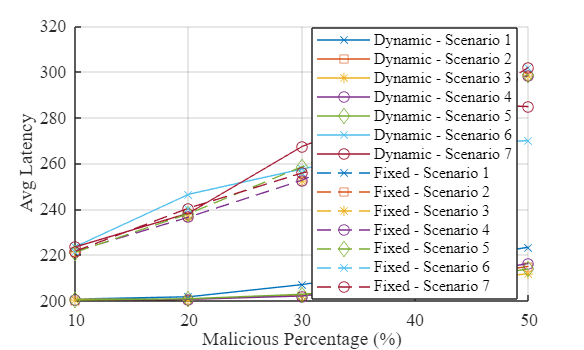

% Extract AvgLatency results for each scenario

dynamicAvgLatencyScenario1 = arrayfun(@(x) x.Dynamic.AvgLatency, allResults_1_3);
dynamicAvgLatencyScenario2 = arrayfun(@(x) x.Dynamic.AvgLatency, allResults_2_2);
dynamicAvgLatencyScenario3 = arrayfun(@(x) x.Dynamic.AvgLatency, allResults_6_2);
dynamicAvgLatencyScenario4 = arrayfun(@(x) x.Dynamic.AvgLatency, allResults_4_2);
dynamicAvgLatencyScenario5 = arrayfun(@(x) x.Dynamic.AvgLatency, allResults_5_2);
dynamicAvgLatencyScenario6 = arrayfun(@(x) x.Dynamic.AvgLatency, allResults_6_3);
dynamicAvgLatencyScenario7 = arrayfun(@(x) x.Dynamic.AvgLatency, allResults_1_2);

fixedAvgLatencyScenario1 = arrayfun(@(x) x.Fixed.AvgLatency, allResults_1_3);
fixedAvgLatencyScenario2 = arrayfun(@(x) x.Fixed.AvgLatency, allResults_2_2);
fixedAvgLatencyScenario3 = arrayfun(@(x) x.Fixed.AvgLatency, allResults_6_2);
fixedAvgLatencyScenario4 = arrayfun(@(x) x.Fixed.AvgLatency, allResults_4_2);
fixedAvgLatencyScenario5 = arrayfun(@(x) x.Fixed.AvgLatency, allResults_5_2);
fixedAvgLatencyScenario6 = arrayfun(@(x) x.Fixed.AvgLatency, allResults_6_3);
fixedAvgLatencyScenario7 = arrayfun(@(x) x.Fixed.AvgLatency, allResults_1_2);

% Plot both configurations on the same plot
figure;
hold on;

% Dynamic configuration
plot(maliciousPercentages, dynamicAvgLatencyScenario1, '-x', 'DisplayName', 'Dynamic - Scenario 1');
plot(maliciousPercentages, dynamicAvgLatencyScenario2, '-s', 'DisplayName', 'Dynamic - Scenario 2');
plot(maliciousPercentages, dynamicAvgLatencyScenario5, '-*', 'DisplayName', 'Dynamic - Scenario 3');
plot(maliciousPercentages, dynamicAvgLatencyScenario6, '-o', 'DisplayName', 'Dynamic - Scenario 4');
plot(maliciousPercentages, dynamicAvgLatencyScenario4, '-d', 'DisplayName', 'Dynamic - Scenario 5');
plot(maliciousPercentages, dynamicAvgLatencyScenario7, '-x', 'DisplayName', 'Dynamic - Scenario 6');
plot(maliciousPercentages, dynamicAvgLatencyScenario3, '-o', 'DisplayName', 'Dynamic - Scenario 7');

% Fixed configuration
plot(maliciousPercentages, fixedAvgLatencyScenario1, '--x', 'DisplayName', 'Fixed - Scenario 1');
plot(maliciousPercentages, fixedAvgLatencyScenario2, '--s', 'DisplayName', 'Fixed - Scenario 2');
plot(maliciousPercentages, fixedAvgLatencyScenario5, '--*', 'DisplayName', 'Fixed - Scenario 3');
plot(maliciousPercentages, fixedAvgLatencyScenario6, '--o', 'DisplayName', 'Fixed - Scenario 4');
plot(maliciousPercentages, fixedAvgLatencyScenario4, '--d', 'DisplayName', 'Fixed - Scenario 5');
plot(maliciousPercentages, fixedAvgLatencyScenario7, '--x', 'DisplayName', 'Fixed - Scenario 6');
plot(maliciousPercentages, fixedAvgLatencyScenario3, '--o', 'DisplayName', 'Fixed - Scenario 7');

% Labels, legend, and title
xlabel('Malicious Percentage (%)');
ylabel('Avg Latency');
%title('Dynamic and Fixed Configuration: Avg Latency Comparison');
legend('Location', 'best');
grid on;
hold off;
% Set font sizes for axes
set(gca, 'FontSize', 10, 'FontName', 'Times');

% Adjust figure size and export settings
set(gcf, 'Position', [100, 100, 1000, 600]); % Adjust figure size for better visualization
set(gcf, 'PaperUnits', 'inches', 'PaperPosition', [0, 0, 6, 4]); % IEEE single-column layout


% Export the plot
print(gcf, 'avg_latency_comparison1.pdf', '-dpdf', '-r300', '-bestfit'); % Save as PDF
print(gcf, 'avg_latency_comparison1.eps', '-depsc', '-r300'); % Save as EPS
export_fig('avg_latency_comparison1.pdf', '-pdf', '-transparent', '-painters');

%----------------------------------------------------%


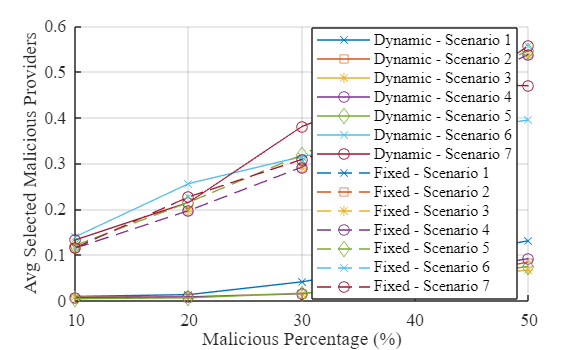

% Extract AvgisMalicious results for each scenario

dynamicAvgisMaliciousScenario1 = arrayfun(@(x) x.Dynamic.AvgisMalicious, allResults_1_3);
dynamicAvgisMaliciousScenario2 = arrayfun(@(x) x.Dynamic.AvgisMalicious, allResults_2_2);
dynamicAvgisMaliciousScenario3 = arrayfun(@(x) x.Dynamic.AvgisMalicious, allResults_6_2);
dynamicAvgisMaliciousScenario4 = arrayfun(@(x) x.Dynamic.AvgisMalicious, allResults_4_2);
dynamicAvgisMaliciousScenario5 = arrayfun(@(x) x.Dynamic.AvgisMalicious, allResults_5_2);
dynamicAvgisMaliciousScenario6 = arrayfun(@(x) x.Dynamic.AvgisMalicious, allResults_6_3);
dynamicAvgisMaliciousScenario7 = arrayfun(@(x) x.Dynamic.AvgisMalicious, allResults_1_2);

fixedAvgisMaliciousScenario1 = arrayfun(@(x) x.Fixed.AvgisMalicious, allResults_1_3);
fixedAvgisMaliciousScenario2 = arrayfun(@(x) x.Fixed.AvgisMalicious, allResults_2_2);
fixedAvgisMaliciousScenario3 = arrayfun(@(x) x.Fixed.AvgisMalicious, allResults_6_2);
fixedAvgisMaliciousScenario4 = arrayfun(@(x) x.Fixed.AvgisMalicious, allResults_4_2);
fixedAvgisMaliciousScenario5 = arrayfun(@(x) x.Fixed.AvgisMalicious, allResults_5_2);
fixedAvgisMaliciousScenario6 = arrayfun(@(x) x.Fixed.AvgisMalicious, allResults_6_3);
fixedAvgisMaliciousScenario7 = arrayfun(@(x) x.Fixed.AvgisMalicious, allResults_1_2);

% Plot both configurations on the same plot
figure;
hold on;

% Dynamic configuration
plot(maliciousPercentages, dynamicAvgisMaliciousScenario1, '-x', 'DisplayName', 'Dynamic - Scenario 1');
plot(maliciousPercentages, dynamicAvgisMaliciousScenario2, '-s', 'DisplayName', 'Dynamic - Scenario 2');
plot(maliciousPercentages, dynamicAvgisMaliciousScenario5, '-*', 'DisplayName', 'Dynamic - Scenario 3');
plot(maliciousPercentages, dynamicAvgisMaliciousScenario6, '-o', 'DisplayName', 'Dynamic - Scenario 4');
plot(maliciousPercentages, dynamicAvgisMaliciousScenario4, '-d', 'DisplayName', 'Dynamic - Scenario 5');
plot(maliciousPercentages, dynamicAvgisMaliciousScenario7, '-x', 'DisplayName', 'Dynamic - Scenario 6');
plot(maliciousPercentages, dynamicAvgisMaliciousScenario3, '-o', 'DisplayName', 'Dynamic - Scenario 7');

% Fixed configuration
plot(maliciousPercentages, fixedAvgisMaliciousScenario1, '--x', 'DisplayName', 'Fixed - Scenario 1');
plot(maliciousPercentages, fixedAvgisMaliciousScenario2, '--s', 'DisplayName', 'Fixed - Scenario 2');
plot(maliciousPercentages, fixedAvgisMaliciousScenario5, '--*', 'DisplayName', 'Fixed - Scenario 3');
plot(maliciousPercentages, fixedAvgisMaliciousScenario6, '--o', 'DisplayName', 'Fixed - Scenario 4');
plot(maliciousPercentages, fixedAvgisMaliciousScenario4, '--d', 'DisplayName', 'Fixed - Scenario 5');
plot(maliciousPercentages, fixedAvgisMaliciousScenario7, '--x', 'DisplayName', 'Fixed - Scenario 6');
plot(maliciousPercentages, fixedAvgisMaliciousScenario3, '--o', 'DisplayName', 'Fixed - Scenario 7');

% Labels, legend, and title
xlabel('Malicious Percentage (%)');
ylabel('Avg Selected Malicious Providers');
%title('Dynamic and Fixed Configuration: Avg Selected Malicious Providers Comparison');
legend('Location', 'best');
grid on;
hold off;
% Set font sizes for axes
set(gca, 'FontSize', 10, 'FontName', 'Times');

% Adjust figure size and export settings
set(gcf, 'Position', [100, 100, 1000, 600]); % Adjust figure size for better visualization
set(gcf, 'PaperUnits', 'inches', 'PaperPosition', [0, 0, 6, 4]); % IEEE single-column layout
% Export the plot
print(gcf, 'avg_Selected_Malicious_comparison1.pdf', '-dpdf', '-r300', '-bestfit'); % Save as PDF
print(gcf, 'avg_Selected_Malicious_comparison1.eps', '-depsc', '-r300'); % Save as EPS
export_fig('avg_Selected_Malicious_comparison1.pdf', '-pdf', '-transparent', '-painters');

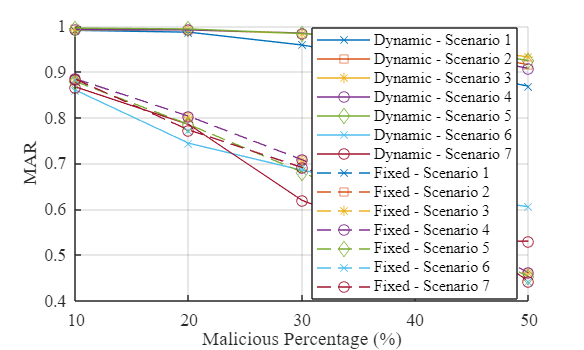

%----------------------------------------------------%
%calculate MAR
dynamicMaliciousAvoidanceRateScenario1 = 1 - dynamicAvgisMaliciousScenario1;
dynamicMaliciousAvoidanceRateScenario2 = 1 - dynamicAvgisMaliciousScenario2;
dynamicMaliciousAvoidanceRateScenario3 = 1 - dynamicAvgisMaliciousScenario3;
dynamicMaliciousAvoidanceRateScenario4 = 1 - dynamicAvgisMaliciousScenario4;
dynamicMaliciousAvoidanceRateScenario5 = 1 - dynamicAvgisMaliciousScenario5;
dynamicMaliciousAvoidanceRateScenario6 = 1 - dynamicAvgisMaliciousScenario6;
dynamicMaliciousAvoidanceRateScenario7 = 1 - dynamicAvgisMaliciousScenario7;

fixedMaliciousAvoidanceRateScenario1 = 1 - fixedAvgisMaliciousScenario1;
fixedMaliciousAvoidanceRateScenario2 = 1 - fixedAvgisMaliciousScenario2;
fixedMaliciousAvoidanceRateScenario3 = 1 - fixedAvgisMaliciousScenario3;
fixedMaliciousAvoidanceRateScenario4 = 1 - fixedAvgisMaliciousScenario4;
fixedMaliciousAvoidanceRateScenario5 = 1 - fixedAvgisMaliciousScenario5;
fixedMaliciousAvoidanceRateScenario6 = 1 - fixedAvgisMaliciousScenario6;
fixedMaliciousAvoidanceRateScenario7 = 1 - fixedAvgisMaliciousScenario7;

% Plot both configurations on the same plot
figure;
hold on;

% Dynamic configuration
plot(maliciousPercentages, dynamicMaliciousAvoidanceRateScenario1, '-x', 'DisplayName', 'Dynamic - Scenario 1');
plot(maliciousPercentages, dynamicMaliciousAvoidanceRateScenario2, '-s', 'DisplayName', 'Dynamic - Scenario 2');
plot(maliciousPercentages, dynamicMaliciousAvoidanceRateScenario5, '-*', 'DisplayName', 'Dynamic - Scenario 3');
plot(maliciousPercentages, dynamicMaliciousAvoidanceRateScenario6, '-o', 'DisplayName', 'Dynamic - Scenario 4');
plot(maliciousPercentages, dynamicMaliciousAvoidanceRateScenario4, '-d', 'DisplayName', 'Dynamic - Scenario 5');
plot(maliciousPercentages, dynamicMaliciousAvoidanceRateScenario7, '-x', 'DisplayName', 'Dynamic - Scenario 6');
plot(maliciousPercentages, dynamicMaliciousAvoidanceRateScenario3, '-o', 'DisplayName', 'Dynamic - Scenario 7');

% Fixed configuration
plot(maliciousPercentages, fixedMaliciousAvoidanceRateScenario1, '--x', 'DisplayName', 'Fixed - Scenario 1');
plot(maliciousPercentages, fixedMaliciousAvoidanceRateScenario2, '--s', 'DisplayName', 'Fixed - Scenario 2');
plot(maliciousPercentages, fixedMaliciousAvoidanceRateScenario5, '--*', 'DisplayName', 'Fixed - Scenario 3');
plot(maliciousPercentages, fixedMaliciousAvoidanceRateScenario6, '--o', 'DisplayName', 'Fixed - Scenario 4');
plot(maliciousPercentages, fixedMaliciousAvoidanceRateScenario4, '--d', 'DisplayName', 'Fixed - Scenario 5');
plot(maliciousPercentages, fixedMaliciousAvoidanceRateScenario7, '--x', 'DisplayName', 'Fixed - Scenario 6');
plot(maliciousPercentages, fixedMaliciousAvoidanceRateScenario3, '--o', 'DisplayName', 'Fixed - Scenario 7');

% Labels, legend, and title
xlabel('Malicious Percentage (%)');
ylabel('MAR');
%title('Dynamic and Fixed Configuration: Malicious Avoidance Rate (MAR) Comparison');
legend('Location', 'best');
grid on;
hold off;
% Set font sizes for axes
set(gca, 'FontSize', 10, 'FontName', 'Times');

% Adjust figure size and export settings
set(gcf, 'Position', [100, 100, 1000, 600]); % Adjust figure size for better visualization
set(gcf, 'PaperUnits', 'inches', 'PaperPosition', [0, 0, 6, 4]); % IEEE single-column layout
% Export the plot
print(gcf, 'mar_comparison1.pdf', '-dpdf', '-r300', '-bestfit'); % Save as PDF
print(gcf, 'mar_comparison1.eps', '-depsc', '-r300'); % Save as EPS
export_fig('mar_comparison1.pdf', '-pdf', '-transparent', '-painters');


%----------------------------------------------------%)


%legend outside
% Load results for the three scenarios
load('simulation_results_1_3.mat');
load('simulation_results_1_2.mat');% random selection skewed high
load('simulation_results_2_2.mat');
load('simulation_results_6_2.mat');%random selection balanced
load('simulation_results_4_2.mat')%random assign
load('simulation_results_5_2.mat')
load('simulation_results_6_3.mat')%scenario6 balanced 
%----------------------------------------------------%
% Define the malicious percentages and success rate data
maliciousPercentages = 10:10:50;

% Extract SuccessRates results for each scenario

dynamicSuccessRatesScenario1 = arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults_1_3);
dynamicSuccessRatesScenario2 = arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults_2_2);
dynamicSuccessRatesScenario3 = arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults_6_2);
dynamicSuccessRatesScenario4 = arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults_4_2);
dynamicSuccessRatesScenario5 = arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults_5_2);
dynamicSuccessRatesScenario6 = arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults_6_3);
dynamicSuccessRatesScenario7 = arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults_1_2);

fixedSuccessRatesScenario1 = arrayfun(@(x) x.Fixed.AvgSuccessRate, allResults_1_3);
fixedSuccessRatesScenario2 = arrayfun(@(x) x.Fixed.AvgSuccessRate, allResults_2_2);
fixedSuccessRatesScenario3 = arrayfun(@(x) x.Fixed.AvgSuccessRate, allResults_6_2);
fixedSuccessRatesScenario4 = arrayfun(@(x) x.Fixed.AvgSuccessRate, allResults_4_2);
fixedSuccessRatesScenario5 = arrayfun(@(x) x.Fixed.AvgSuccessRate, allResults_5_2);
fixedSuccessRatesScenario6 = arrayfun(@(x) x.Fixed.AvgSuccessRate, allResults_6_3);
fixedSuccessRatesScenario7 = arrayfun(@(x) x.Fixed.AvgSuccessRate, allResults_1_2);

% Plot both configurations on the same plot
figure;
hold on;

% Dynamic configuration
plot(maliciousPercentages, dynamicSuccessRatesScenario1, '-x', 'DisplayName', 'Dynamic - Scenario 1');
plot(maliciousPercentages, dynamicSuccessRatesScenario2, '-s', 'DisplayName', 'Dynamic - Scenario 2');
plot(maliciousPercentages, dynamicSuccessRatesScenario5, '-*', 'DisplayName', 'Dynamic - Scenario 3');
plot(maliciousPercentages, dynamicSuccessRatesScenario6, '-o', 'DisplayName', 'Dynamic - Scenario 4');
plot(maliciousPercentages, dynamicSuccessRatesScenario4, '-d', 'DisplayName', 'Dynamic - Scenario 5');
plot(maliciousPercentages, dynamicSuccessRatesScenario7, '-x', 'DisplayName', 'Dynamic - Scenario 6');
plot(maliciousPercentages, dynamicSuccessRatesScenario3, '-o', 'DisplayName', 'Dynamic - Scenario 7');

% Fixed configuration
plot(maliciousPercentages, fixedSuccessRatesScenario1, '--x', 'DisplayName', 'Fixed - Scenario 1');
plot(maliciousPercentages, fixedSuccessRatesScenario2, '--s', 'DisplayName', 'Fixed - Scenario 2');
plot(maliciousPercentages, fixedSuccessRatesScenario5, '--*', 'DisplayName', 'Fixed - Scenario 3');
plot(maliciousPercentages, fixedSuccessRatesScenario6, '--o', 'DisplayName', 'Fixed - Scenario 4');
plot(maliciousPercentages, fixedSuccessRatesScenario4, '--d', 'DisplayName', 'Fixed - Scenario 5');
plot(maliciousPercentages, fixedSuccessRatesScenario7, '--x', 'DisplayName', 'Fixed - Scenario 6');
plot(maliciousPercentages, fixedSuccessRatesScenario3, '--o', 'DisplayName', 'Fixed - Scenario 7');


% Labels, title, and legend
xlabel('Malicious Percentage (%)', 'FontSize', 12, 'FontName', 'Times');
ylabel('Success Rate', 'FontSize', 12, 'FontName', 'Times');
title({'Dynamic and Fixed Configuration:',' Success Rate Comparison'}, 'FontSize', 14, 'FontName', 'Times');
%legend('Location', 'northeastoutside', 'FontSize', 10); % Legend outside the plot area


% Grid and limits
grid on;
xlim([10 50]); % Set x-axis limits
ylim auto;

% Set font sizes for axes
set(gca, 'FontSize', 10, 'FontName', 'Times');
hold off;
% Adjust figure size and export settings
set(gcf, 'Position', [100, 100, 1000, 600]); % Adjust figure size for better visualization
set(gcf, 'PaperUnits', 'inches', 'PaperPosition', [0, 0, 6, 4]); % IEEE single-column layout

% Export the plot in high resolution
print(gcf, 'success_rate_comparison2.pdf', '-dpdf', '-r300', '-bestfit'); % Save as PDF
print(gcf, 'success_rate_comparison2.eps', '-depsc', '-r300'); % Save as EPS
%----------------------------------------------------%



% Extract AvgLatency results for each scenario

dynamicAvgLatencyScenario1 = arrayfun(@(x) x.Dynamic.AvgLatency, allResults_1_3);
dynamicAvgLatencyScenario2 = arrayfun(@(x) x.Dynamic.AvgLatency, allResults_2_2);
dynamicAvgLatencyScenario3 = arrayfun(@(x) x.Dynamic.AvgLatency, allResults_6_2);
dynamicAvgLatencyScenario4 = arrayfun(@(x) x.Dynamic.AvgLatency, allResults_4_2);
dynamicAvgLatencyScenario5 = arrayfun(@(x) x.Dynamic.AvgLatency, allResults_5_2);
dynamicAvgLatencyScenario6 = arrayfun(@(x) x.Dynamic.AvgLatency, allResults_6_3);
dynamicAvgLatencyScenario7 = arrayfun(@(x) x.Dynamic.AvgLatency, allResults_1_2);

fixedAvgLatencyScenario1 = arrayfun(@(x) x.Fixed.AvgLatency, allResults_1_3);
fixedAvgLatencyScenario2 = arrayfun(@(x) x.Fixed.AvgLatency, allResults_2_2);
fixedAvgLatencyScenario3 = arrayfun(@(x) x.Fixed.AvgLatency, allResults_6_2);
fixedAvgLatencyScenario4 = arrayfun(@(x) x.Fixed.AvgLatency, allResults_4_2);
fixedAvgLatencyScenario5 = arrayfun(@(x) x.Fixed.AvgLatency, allResults_5_2);
fixedAvgLatencyScenario6 = arrayfun(@(x) x.Fixed.AvgLatency, allResults_6_3);
fixedAvgLatencyScenario7 = arrayfun(@(x) x.Fixed.AvgLatency, allResults_1_2);

% Plot both configurations on the same plot
figure;
hold on;

% Dynamic configuration
plot(maliciousPercentages, dynamicAvgLatencyScenario1, '-x', 'DisplayName', 'Dynamic - Scenario 1');
plot(maliciousPercentages, dynamicAvgLatencyScenario2, '-s', 'DisplayName', 'Dynamic - Scenario 2');
plot(maliciousPercentages, dynamicAvgLatencyScenario5, '-*', 'DisplayName', 'Dynamic - Scenario 3');
plot(maliciousPercentages, dynamicAvgLatencyScenario6, '-o', 'DisplayName', 'Dynamic - Scenario 4');
plot(maliciousPercentages, dynamicAvgLatencyScenario4, '-d', 'DisplayName', 'Dynamic - Scenario 5');
plot(maliciousPercentages, dynamicAvgLatencyScenario7, '-x', 'DisplayName', 'Dynamic - Scenario 6');
plot(maliciousPercentages, dynamicAvgLatencyScenario3, '-o', 'DisplayName', 'Dynamic - Scenario 7');

% Fixed configuration
plot(maliciousPercentages, fixedAvgLatencyScenario1, '--x', 'DisplayName', 'Fixed - Scenario 1');
plot(maliciousPercentages, fixedAvgLatencyScenario2, '--s', 'DisplayName', 'Fixed - Scenario 2');
plot(maliciousPercentages, fixedAvgLatencyScenario5, '--*', 'DisplayName', 'Fixed - Scenario 3');
plot(maliciousPercentages, fixedAvgLatencyScenario6, '--o', 'DisplayName', 'Fixed - Scenario 4');
plot(maliciousPercentages, fixedAvgLatencyScenario4, '--d', 'DisplayName', 'Fixed - Scenario 5');
plot(maliciousPercentages, fixedAvgLatencyScenario7, '--x', 'DisplayName', 'Fixed - Scenario 6');
plot(maliciousPercentages, fixedAvgLatencyScenario3, '--o', 'DisplayName', 'Fixed - Scenario 7');

% Labels, legend, and title
xlabel('Malicious Percentage (%)');
ylabel('Avg Latency');
title({'Dynamic and Fixed Configuration:' ,'Avg Latency Comparison'});
legend('Location', 'northeastoutside', 'FontSize', 10); % Legend outside the plot area

% Grid and limits
grid on;
xlim([10 50]); % Set x-axis limits
ylim auto;

% Set font sizes for axes
set(gca, 'FontSize', 10, 'FontName', 'Times');
hold off;
% Adjust figure size and export settings
set(gcf, 'Position', [100, 100, 1000, 600]); % Adjust figure size for better visualization
set(gcf, 'PaperUnits', 'inches', 'PaperPosition', [0, 0, 6, 4]); % IEEE single-column layout

% Export the plot
print(gcf, 'avg_latency_comparison.pdf', '-dpdf', '-r300', '-bestfit'); % Save as PDF
print(gcf, 'avg_latency_comparison.eps', '-depsc', '-r300'); % Save as EPS
%----------------------------------------------------%

% Extract AvgisMaliciousS results for each scenario

dynamicAvgisMaliciousScenario1 = arrayfun(@(x) x.Dynamic.AvgisMalicious, allResults_1_3);
dynamicAvgisMaliciousScenario2 = arrayfun(@(x) x.Dynamic.AvgisMalicious, allResults_2_2);
dynamicAvgisMaliciousScenario3 = arrayfun(@(x) x.Dynamic.AvgisMalicious, allResults_6_2);
dynamicAvgisMaliciousScenario4 = arrayfun(@(x) x.Dynamic.AvgisMalicious, allResults_4_2);
dynamicAvgisMaliciousScenario5 = arrayfun(@(x) x.Dynamic.AvgisMalicious, allResults_5_2);
dynamicAvgisMaliciousScenario6 = arrayfun(@(x) x.Dynamic.AvgisMalicious, allResults_6_3);
dynamicAvgisMaliciousScenario7 = arrayfun(@(x) x.Dynamic.AvgisMalicious, allResults_1_2);

fixedAvgisMaliciousScenario1 = arrayfun(@(x) x.Fixed.AvgisMalicious, allResults_1_3);
fixedAvgisMaliciousScenario2 = arrayfun(@(x) x.Fixed.AvgisMalicious, allResults_2_2);
fixedAvgisMaliciousScenario3 = arrayfun(@(x) x.Fixed.AvgisMalicious, allResults_6_2);
fixedAvgisMaliciousScenario4 = arrayfun(@(x) x.Fixed.AvgisMalicious, allResults_4_2);
fixedAvgisMaliciousScenario5 = arrayfun(@(x) x.Fixed.AvgisMalicious, allResults_5_2);
fixedAvgisMaliciousScenario6 = arrayfun(@(x) x.Fixed.AvgisMalicious, allResults_6_3);
fixedAvgisMaliciousScenario7 = arrayfun(@(x) x.Fixed.AvgisMalicious, allResults_1_2);

% Plot both configurations on the same plot
figure;
hold on;

% Dynamic configuration
plot(maliciousPercentages, dynamicAvgisMaliciousScenario1, '-x', 'DisplayName', 'Dynamic - Scenario 1');
plot(maliciousPercentages, dynamicAvgisMaliciousScenario2, '-s', 'DisplayName', 'Dynamic - Scenario 2');
plot(maliciousPercentages, dynamicAvgisMaliciousScenario5, '-*', 'DisplayName', 'Dynamic - Scenario 3');
plot(maliciousPercentages, dynamicAvgisMaliciousScenario6, '-o', 'DisplayName', 'Dynamic - Scenario 4');
plot(maliciousPercentages, dynamicAvgisMaliciousScenario4, '-d', 'DisplayName', 'Dynamic - Scenario 5');
plot(maliciousPercentages, dynamicAvgisMaliciousScenario7, '-x', 'DisplayName', 'Dynamic - Scenario 6');
plot(maliciousPercentages, dynamicAvgisMaliciousScenario3, '-o', 'DisplayName', 'Dynamic - Scenario 7');

% Fixed configuration
plot(maliciousPercentages, fixedAvgisMaliciousScenario1, '--x', 'DisplayName', 'Fixed - Scenario 1');
plot(maliciousPercentages, fixedAvgisMaliciousScenario2, '--s', 'DisplayName', 'Fixed - Scenario 2');
plot(maliciousPercentages, fixedAvgisMaliciousScenario5, '--*', 'DisplayName', 'Fixed - Scenario 3');
plot(maliciousPercentages, fixedAvgisMaliciousScenario6, '--o', 'DisplayName', 'Fixed - Scenario 4');
plot(maliciousPercentages, fixedAvgisMaliciousScenario4, '--d', 'DisplayName', 'Fixed - Scenario 5');
plot(maliciousPercentages, fixedAvgisMaliciousScenario7, '--x', 'DisplayName', 'Fixed - Scenario 6');
plot(maliciousPercentages, fixedAvgisMaliciousScenario3, '--o', 'DisplayName', 'Fixed - Scenario 7');

% Labels, legend, and title
xlabel('Malicious Percentage (%)');
ylabel('Avg Selected Malicious Providers');
title({'Dynamic and Fixed Configuration:', 'Avg Selected Malicious Providers Comparison'});
legend('Location', 'northeastoutside', 'FontSize', 10); % Legend outside the plot area

% Grid and limits
grid on;
xlim([10 50]); % Set x-axis limits
ylim auto;

% Set font sizes for axes
set(gca, 'FontSize', 10, 'FontName', 'Times');
hold off;
% Adjust figure size and export settings
set(gcf, 'Position', [100, 100, 1000, 600]); % Adjust figure size for better visualization
set(gcf, 'PaperUnits', 'inches', 'PaperPosition', [0, 0, 6, 4]); % IEEE single-column layout
% Export the plot
print(gcf, 'avg_Selected_Malicious_comparison.pdf', '-dpdf', '-r300', '-bestfit'); % Save as PDF
print(gcf, 'avg_Selected_Malicious_comparison.eps', '-depsc', '-r300'); % Save as EPS

%----------------------------------------------------%
%calculate MAR
dynamicMaliciousAvoidanceRateScenario1 = 1 - dynamicAvgisMaliciousScenario1;
dynamicMaliciousAvoidanceRateScenario2 = 1 - dynamicAvgisMaliciousScenario2;
dynamicMaliciousAvoidanceRateScenario3 = 1 - dynamicAvgisMaliciousScenario3;
dynamicMaliciousAvoidanceRateScenario4 = 1 - dynamicAvgisMaliciousScenario4;
dynamicMaliciousAvoidanceRateScenario5 = 1 - dynamicAvgisMaliciousScenario5;
dynamicMaliciousAvoidanceRateScenario6 = 1 - dynamicAvgisMaliciousScenario6;
dynamicMaliciousAvoidanceRateScenario7 = 1 - dynamicAvgisMaliciousScenario7;

fixedMaliciousAvoidanceRateScenario1 = 1 - fixedAvgisMaliciousScenario1;
fixedMaliciousAvoidanceRateScenario2 = 1 - fixedAvgisMaliciousScenario2;
fixedMaliciousAvoidanceRateScenario3 = 1 - fixedAvgisMaliciousScenario3;
fixedMaliciousAvoidanceRateScenario4 = 1 - fixedAvgisMaliciousScenario4;
fixedMaliciousAvoidanceRateScenario5 = 1 - fixedAvgisMaliciousScenario5;
fixedMaliciousAvoidanceRateScenario6 = 1 - fixedAvgisMaliciousScenario6;
fixedMaliciousAvoidanceRateScenario7 = 1 - fixedAvgisMaliciousScenario7;

% Plot both configurations on the same plot
figure;
hold on;

% Dynamic configuration
plot(maliciousPercentages, dynamicMaliciousAvoidanceRateScenario1, '-x', 'DisplayName', 'Dynamic - Scenario 1');
plot(maliciousPercentages, dynamicMaliciousAvoidanceRateScenario2, '-s', 'DisplayName', 'Dynamic - Scenario 2');
plot(maliciousPercentages, dynamicMaliciousAvoidanceRateScenario5, '-*', 'DisplayName', 'Dynamic - Scenario 3');
plot(maliciousPercentages, dynamicMaliciousAvoidanceRateScenario6, '-o', 'DisplayName', 'Dynamic - Scenario 4');
plot(maliciousPercentages, dynamicMaliciousAvoidanceRateScenario4, '-d', 'DisplayName', 'Dynamic - Scenario 5');
plot(maliciousPercentages, dynamicMaliciousAvoidanceRateScenario7, '-x', 'DisplayName', 'Dynamic - Scenario 6');
plot(maliciousPercentages, dynamicMaliciousAvoidanceRateScenario3, '-o', 'DisplayName', 'Dynamic - Scenario 7');

% Fixed configuration
plot(maliciousPercentages, fixedMaliciousAvoidanceRateScenario1, '--x', 'DisplayName', 'Fixed - Scenario 1');
plot(maliciousPercentages, fixedMaliciousAvoidanceRateScenario2, '--s', 'DisplayName', 'Fixed - Scenario 2');
plot(maliciousPercentages, fixedMaliciousAvoidanceRateScenario5, '--*', 'DisplayName', 'Fixed - Scenario 3');
plot(maliciousPercentages, fixedMaliciousAvoidanceRateScenario6, '--o', 'DisplayName', 'Fixed - Scenario 4');
plot(maliciousPercentages, fixedMaliciousAvoidanceRateScenario4, '--d', 'DisplayName', 'Fixed - Scenario 5');
plot(maliciousPercentages, fixedMaliciousAvoidanceRateScenario7, '--x', 'DisplayName', 'Fixed - Scenario 6');
plot(maliciousPercentages, fixedMaliciousAvoidanceRateScenario3, '--o', 'DisplayName', 'Fixed - Scenario 7');

% Labels, legend, and title
xlabel('Malicious Percentage (%)');
ylabel('MAR');
title({'Dynamic and Fixed Configuration:', 'Avg Malicious Avoidance Rate (MAR) Comparison'});
legend('Location', 'northeastoutside', 'FontSize', 10); % Legend outside the plot area

% Grid and limits
grid on;
xlim([10 50]); % Set x-axis limits
ylim auto;

% Set font sizes for axes
set(gca, 'FontSize', 10, 'FontName', 'Times');
hold off;
% Adjust figure size and export settings
set(gcf, 'Position', [100, 100, 1000, 600]); % Adjust figure size for better visualization
set(gcf, 'PaperUnits', 'inches', 'PaperPosition', [0, 0, 6, 4]); % IEEE single-column layout


% Export the plot
print(gcf, 'mar_comparison.pdf', '-dpdf', '-r300', '-bestfit'); % Save as PDF
print(gcf, 'mar_comparison.eps', '-depsc', '-r300'); % Save as EPS

%----------------------------------------------------%

% Extract initial and Initial and updated reputation for dynamic configurations
dynamicAvgInitialReputationScenario1 = arrayfun(@(x) x.Dynamic.AvgInitialReputation, allResults_1_3);
dynamicAvgInitialReputationScenario2 = arrayfun(@(x) x.Dynamic.AvgInitialReputation, allResults_2_2);
dynamicAvgInitialReputationScenario3 = arrayfun(@(x) x.Dynamic.AvgInitialReputation, allResults_6_2);
dynamicAvgInitialReputationScenario4 = arrayfun(@(x) x.Dynamic.AvgInitialReputation, allResults_4_2);
dynamicAvgInitialReputationScenario5 = arrayfun(@(x) x.Dynamic.AvgInitialReputation, allResults_5_2);
dynamicAvgInitialReputationScenario6 = arrayfun(@(x) x.Dynamic.AvgInitialReputation, allResults_6_3);
dynamicAvgInitialReputationScenario7 = arrayfun(@(x) x.Dynamic.AvgInitialReputation, allResults_1_2);

dynamicAvgUpdatedReputationScenario1 = arrayfun(@(x) x.Dynamic.AvgUpdateReputation, allResults_1_3);
dynamicAvgUpdatedReputationScenario2 = arrayfun(@(x) x.Dynamic.AvgUpdateReputation, allResults_2_2);
dynamicAvgUpdatedReputationScenario3 = arrayfun(@(x) x.Dynamic.AvgUpdateReputation, allResults_6_2);
dynamicAvgUpdatedReputationScenario4 = arrayfun(@(x) x.Dynamic.AvgUpdateReputation, allResults_4_2);
dynamicAvgUpdatedReputationScenario5 = arrayfun(@(x) x.Dynamic.AvgUpdateReputation, allResults_5_2);
dynamicAvgUpdatedReputationScenario6 = arrayfun(@(x) x.Dynamic.AvgUpdateReputation, allResults_6_3);
dynamicAvgUpdatedReputationScenario7 = arrayfun(@(x) x.Dynamic.AvgUpdateReputation, allResults_1_2);

fixedAvgInitialReputationScenario1 = arrayfun(@(x) x.Fixed.AvgInitialReputation, allResults_1_3);
fixedAvgInitialReputationScenario2 = arrayfun(@(x) x.Fixed.AvgInitialReputation, allResults_2_2);
fixedAvgInitialReputationScenario3 = arrayfun(@(x) x.Fixed.AvgInitialReputation, allResults_6_2);
fixedAvgInitialReputationScenario4 = arrayfun(@(x) x.Fixed.AvgInitialReputation, allResults_4_2);
fixedAvgInitialReputationScenario5 = arrayfun(@(x) x.Fixed.AvgInitialReputation, allResults_5_2);
fixedAvgInitialReputationScenario6 = arrayfun(@(x) x.Fixed.AvgInitialReputation, allResults_6_3);
fixedAvgInitialReputationScenario7 = arrayfun(@(x) x.Fixed.AvgInitialReputation, allResults_1_2);

fixedAvgUpdatedReputationScenario1 = arrayfun(@(x) x.Fixed.AvgUpdateReputation, allResults_1_3);
fixedAvgUpdatedReputationScenario2 = arrayfun(@(x) x.Fixed.AvgUpdateReputation, allResults_2_2);
fixedAvgUpdatedReputationScenario3 = arrayfun(@(x) x.Fixed.AvgUpdateReputation, allResults_6_2);
fixedAvgUpdatedReputationScenario4 = arrayfun(@(x) x.Fixed.AvgUpdateReputation, allResults_4_2);
fixedAvgUpdatedReputationScenario5 = arrayfun(@(x) x.Fixed.AvgUpdateReputation, allResults_5_2);
fixedAvgUpdatedReputationScenario6 = arrayfun(@(x) x.Fixed.AvgUpdateReputation, allResults_6_3);
fixedAvgUpdatedReputationScenario7 = arrayfun(@(x) x.Fixed.AvgUpdateReputation, allResults_1_2);


dataMatrix = [
    dynamicAvgInitialReputationScenario1', dynamicAvgUpdatedReputationScenario1', fixedAvgInitialReputationScenario1', fixedAvgUpdatedReputationScenario1';
    dynamicAvgInitialReputationScenario2', dynamicAvgUpdatedReputationScenario2', fixedAvgInitialReputationScenario2', fixedAvgUpdatedReputationScenario2';
    dynamicAvgInitialReputationScenario3', dynamicAvgUpdatedReputationScenario3', fixedAvgInitialReputationScenario3', fixedAvgUpdatedReputationScenario3';
    dynamicAvgInitialReputationScenario4', dynamicAvgUpdatedReputationScenario4', fixedAvgInitialReputationScenario4', fixedAvgUpdatedReputationScenario4';
    dynamicAvgInitialReputationScenario5', dynamicAvgUpdatedReputationScenario5', fixedAvgInitialReputationScenario5', fixedAvgUpdatedReputationScenario5';
    dynamicAvgInitialReputationScenario6', dynamicAvgUpdatedReputationScenario6', fixedAvgInitialReputationScenario6', fixedAvgUpdatedReputationScenario6';
    dynamicAvgInitialReputationScenario7', dynamicAvgUpdatedReputationScenario7', fixedAvgInitialReputationScenario7', fixedAvgUpdatedReputationScenario7'
];

% Reshape to create 7 groups (one per scenario), each with 5 sub-groups (one per malicious percentage)
dataMatrix = reshape(dataMatrix, 35, 4);

% Generate x-axis labels for all groups (5 groups per scenario)
xLabels = {};
for scenarioIdx = 1:7
    for percentageIdx = 1:5
        xLabels{end+1} = sprintf('Scenario %d (%d%%)', scenarioIdx, percentageIdx * 10);
    end
end

% Create the grouped bar chart
figure;
bar(dataMatrix, 'grouped');

% Update x-axis labels
set(gca, 'XTick', 1:size(dataMatrix, 1), 'XTickLabel', xLabels);

% Rotate x-axis labels for better readability
xtickangle(45);

% Add labels, title, and legend
xlabel('Scenarios and Malicious Percentages', 'FontSize', 14);
ylabel('Reputation Score', 'FontSize', 14);
title('Reputation Distribution Across Scenarios and Malicious Percentages', 'FontSize', 16);

legend({'Dynamic Initial', 'Dynamic Updated', 'Fixed Initial', 'Fixed Updated'}, ...
       'Location', 'northwest', 'FontSize', 12);

% Add grid and adjust y-axis limits
grid on;
ylim([0 1]); % Reputation scores range from 0 to 1



% % Create the grouped bar chart
% figure;
% bar(dataMatrix, 'grouped');
% 
% % Update x-axis labels
% set(gca, 'XTick', 1:size(dataMatrix, 1), 'XTickLabel', xLabels);
% 
% % Rotate x-axis labels for better readability
% xtickangle(45);
% 
% % Add labels, title, and legend
% xlabel('Scenarios and Malicious Percentages', 'FontSize', 14);
% ylabel('Reputation Score', 'FontSize', 14);
% title('Reputation Distribution Across Scenarios and Malicious Percentages', 'FontSize', 16);
% 
% legend({'Dynamic Initial', 'Dynamic Updated', 'Fixed Initial', 'Fixed Updated'}, ...
%        'Location', 'northwest', 'FontSize', 12);
% 
% % Add grid and adjust y-axis limits
% grid on;
% ylim([0 1]); % Reputation scores range from 0 to 1

% Export the plot
print(gcf, 'reputation_distribution.pdf', '-dpdf', '-r300'); % Save as PDF
print(gcf, 'reputation_distribution.eps', '-depsc', '-r300'); % Save as EPS


% Improved MATLAB Code for IEEE-Compliant Figure

% Improved MATLAB Code for Grouped Bar Chart

% Data Preparation (Replace with your actual data)
dynamicAvgInitialReputationScenario1 = rand(1, 5) * 0.8; % Example data
dynamicAvgUpdatedReputationScenario1 = dynamicAvgInitialReputationScenario1 + 0.1; % Example data
fixedAvgInitialReputationScenario1 = rand(1, 5) * 0.8; % Example data
fixedAvgUpdatedReputationScenario1 = fixedAvgInitialReputationScenario1 + 0.1; % Example data

% Combine into a data matrix for the grouped bar plot
dataMatrix = [
    dynamicAvgInitialReputationScenario1', dynamicAvgUpdatedReputationScenario1', ...
    fixedAvgInitialReputationScenario1', fixedAvgUpdatedReputationScenario1'
];

% X-axis labels for each scenario and percentage
xLabels = {'Scenario 1 (10%)', 'Scenario 1 (20%)', 'Scenario 1 (30%)', ...
           'Scenario 1 (40%)', 'Scenario 1 (50%)'};

% Create the figure with specific size
figure;
set(gcf, 'Position', [100, 100, 1000, 600]); % Adjust on-screen size

% Create the grouped bar chart
b = bar(dataMatrix, 'grouped', 'BarWidth', 0.8); % Adjust bar width

% Customize bar colors
b(1).CData = repmat([0 0.447 0.741], size(dataMatrix, 1), 1); % Blue
b(2).CData = repmat([0.850 0.325 0.098], size(dataMatrix, 1), 1); % Orange
b(3).CData = repmat([0.929 0.694 0.125], size(dataMatrix, 1), 1); % Yellow
b(4).CData = repmat([0.494 0.184 0.556], size(dataMatrix, 1), 1); % Purple

% Update x-axis labels
set(gca, 'XTick', 1:size(dataMatrix, 1), 'XTickLabel', xLabels, 'FontSize', 10, 'FontName', 'Times');
xtickangle(45); % Rotate x-axis labels

% Add labels, title, and legend
xlabel('Scenarios and Malicious Percentages', 'FontSize', 12, 'FontName', 'Times');
ylabel('Reputation Score', 'FontSize', 12, 'FontName', 'Times');
title('Reputation Distribution Across Scenarios and Malicious Percentages', ...
      'FontSize', 14, 'FontName', 'Times');
legend({'Dynamic Initial', 'Dynamic Updated', 'Fixed Initial', 'Fixed Updated'}, ...
       'Location', 'northeastoutside', 'FontSize', 10);

% Add grid and adjust y-axis limits
grid on;
set(gca, 'YGrid', 'on', 'XGrid', 'off'); % Horizontal gridlines only
ylim([0 1]); % Reputation scores range from 0 to 1

% Set font sizes and styles for axis ticks
set(gca, 'FontSize', 10, 'FontName', 'Times');

% Adjust paper size for export
set(gcf, 'PaperUnits', 'inches', 'PaperPosition', [0, 0, 6, 4]); % IEEE single-column

% Export the figure
print(gcf, 'reputation_distribution.pdf', '-dpdf', '-r300', '-bestfit'); % Save as PDF
print(gcf, 'reputation_distribution.eps', '-depsc', '-r300'); % Save as EPS



% Create a tiled layout with 3 rows and 1 column
tiledlayout(3, 1);

% Plot 1: Success Rate Comparison
nexttile;

%the old probabilities 
% Load results for the three scenarios
load('simulation_results_1.mat');
load('simulation_results_2.mat');
load('simulation_results_3_random.mat');
load('simulation_results_4_randomAssign.mat')
load('simulation_results_5.mat')
load('simulation_results_6.mat')
%----------------------------------------------------%
% Define the malicious percentages and success rate data
% Replace these placeholders with your actual data
maliciousPercentages = 10:10:50;


% Extract results for each scenario
%dynamicSuccessRatesScenario = arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults);
dynamicSuccessRatesScenario1 = arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults_1);
dynamicSuccessRatesScenario2 = arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults_2);
dynamicSuccessRatesScenario3 = arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults_3_random);
dynamicSuccessRatesScenario4 = arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults_4_randomAssign);
dynamicSuccessRatesScenario5 = arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults_5);
dynamicSuccessRatesScenario6 = arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults_6);

%fixedSuccessRatesScenario = arrayfun(@(x) x.Fixed.AvgSuccessRate, allResults);
fixedSuccessRatesScenario1 = arrayfun(@(x) x.Fixed.AvgSuccessRate, allResults_1);
fixedSuccessRatesScenario2 = arrayfun(@(x) x.Fixed.AvgSuccessRate, allResults_2);
fixedSuccessRatesScenario3 = arrayfun(@(x) x.Fixed.AvgSuccessRate, allResults_3_random);
fixedSuccessRatesScenario4 = arrayfun(@(x) x.Fixed.AvgSuccessRate, allResults_4_randomAssign);
fixedSuccessRatesScenario5 = arrayfun(@(x) x.Fixed.AvgSuccessRate, allResults_5);
fixedSuccessRatesScenario6 = arrayfun(@(x) x.Fixed.AvgSuccessRate, allResults_6);

% Plot both configurations on the same plot
figure;
hold on;

% Dynamic configuration
plot(maliciousPercentages, dynamicSuccessRatesScenario1, '-x', 'DisplayName', 'Dynamic - Scenario 1');
plot(maliciousPercentages, dynamicSuccessRatesScenario2, '-s', 'DisplayName', 'Dynamic - Scenario 2');
plot(maliciousPercentages, dynamicSuccessRatesScenario5, '-*', 'DisplayName', 'Dynamic - Scenario 3');
plot(maliciousPercentages, dynamicSuccessRatesScenario6, '-o', 'DisplayName', 'Dynamic - Scenario 4');
plot(maliciousPercentages, dynamicSuccessRatesScenario4, '-d', 'DisplayName', 'Dynamic - Scenario 5');
plot(maliciousPercentages, dynamicSuccessRatesScenario3, '-s', 'DisplayName', 'Dynamic - Scenario 6');

% Fixed configuration
plot(maliciousPercentages, fixedSuccessRatesScenario1, '--x', 'DisplayName', 'Fixed - Scenario 1');
plot(maliciousPercentages, fixedSuccessRatesScenario2, '--s', 'DisplayName', 'Fixed - Scenario 2');
plot(maliciousPercentages, fixedSuccessRatesScenario5, '--*', 'DisplayName', 'Fixed - Scenario 3');
plot(maliciousPercentages, fixedSuccessRatesScenario6, '--o', 'DisplayName', 'Fixed - Scenario 4');
plot(maliciousPercentages, fixedSuccessRatesScenario4, '--d', 'DisplayName', 'Fixed - Scenario 5');
plot(maliciousPercentages, fixedSuccessRatesScenario3, '--s', 'DisplayName', 'Fixed - Scenario 6');

% Labels, legend, and title
xlabel('Malicious Percentage (%)');
ylabel('Success Rate');
title('Dynamic and Fixed Configuration: Success Rate Comparison');
legend('Location', 'best');
grid on;
hold off;
% Extract results for each scenario
%dynamicSuccessRatesScenario = arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults);
dynamicAvgLatencyScenario1 = arrayfun(@(x) x.Dynamic.AvgLatency, allResults_1);
dynamicAvgLatencyScenario2 = arrayfun(@(x) x.Dynamic.AvgLatency, allResults_2);
dynamicAvgLatencyScenario3 = arrayfun(@(x) x.Dynamic.AvgLatency, allResults_3_random);
dynamicAvgLatencyScenario4 = arrayfun(@(x) x.Dynamic.AvgLatency, allResults_4_randomAssign);
dynamicAvgLatencyScenario5 = arrayfun(@(x) x.Dynamic.AvgLatency, allResults_5);

%fixedSuccessRatesScenario = arrayfun(@(x) x.Fixed.AvgSuccessRate, allResults);
fixedAvgLatencyScenario1 = arrayfun(@(x) x.Fixed.AvgLatency, allResults_1);
fixedAvgLatencyScenario2 = arrayfun(@(x) x.Fixed.AvgLatency, allResults_2);
fixedAvgLatencyScenario3 = arrayfun(@(x) x.Fixed.AvgLatency, allResults_3_random);
fixedAvgLatencyScenario4 = arrayfun(@(x) x.Fixed.AvgLatency, allResults_4_randomAssign);
fixedAvgLatencyScenario5 = arrayfun(@(x) x.Fixed.AvgLatency, allResults_5);

% Plot both configurations on the same plot
figure;
hold on;

% Dynamic configuration
plot(maliciousPercentages, dynamicAvgLatencyScenario1, '-x', 'DisplayName', 'Dynamic - Scenario 1');
plot(maliciousPercentages, dynamicAvgLatencyScenario2, '-s', 'DisplayName', 'Dynamic - Scenario 2');
plot(maliciousPercentages, dynamicAvgLatencyScenario5, '-*', 'DisplayName', 'Dynamic - Scenario 3');
plot(maliciousPercentages, dynamicAvgLatencyScenario4, '-o', 'DisplayName', 'Dynamic - Scenario 4');
plot(maliciousPercentages, dynamicAvgLatencyScenario3, '-d', 'DisplayName', 'Dynamic - Scenario 5');

% Fixed configuration
plot(maliciousPercentages, fixedAvgLatencyScenario1, '--x', 'DisplayName', 'Fixed - Scenario 1');
plot(maliciousPercentages, fixedAvgLatencyScenario2, '--s', 'DisplayName', 'Fixed - Scenario 2');
plot(maliciousPercentages, fixedAvgLatencyScenario5, '--*', 'DisplayName', 'Fixed - Scenario 3');
plot(maliciousPercentages, fixedAvgLatencyScenario4, '--o', 'DisplayName', 'Fixed - Scenario 4');
plot(maliciousPercentages, fixedAvgLatencyScenario3, '--d', 'DisplayName', 'Fixed - Scenario 5');

% Labels, legend, and title
xlabel('Malicious Percentage (%)');
ylabel('Avg Latency');
title('Dynamic and Fixed Configuration: Avg Latency Comparison');
legend('Location', 'best');
grid on;
hold off;
% Extract results for each scenario
%dynamicSuccessRatesScenario = arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults);
dynamicAvgisMaliciousScenario1 = arrayfun(@(x) x.Dynamic.AvgisMalicious, allResults_1);
dynamicAvgisMaliciousScenario2 = arrayfun(@(x) x.Dynamic.AvgisMalicious, allResults_2);
dynamicAvgisMaliciousScenario3 = arrayfun(@(x) x.Dynamic.AvgisMalicious, allResults_3_random);
dynamicAvgisMaliciousScenario4 = arrayfun(@(x) x.Dynamic.AvgisMalicious, allResults_4_randomAssign);
dynamicAvgisMaliciousScenario5 = arrayfun(@(x) x.Dynamic.AvgisMalicious, allResults_5);

%fixedSuccessRatesScenario = arrayfun(@(x) x.Fixed.AvgSuccessRate, allResults);
fixedAvgisMaliciousScenario1 = arrayfun(@(x) x.Fixed.AvgisMalicious, allResults_1);
fixedAvgisMaliciousScenario2 = arrayfun(@(x) x.Fixed.AvgisMalicious, allResults_2);
fixedAvgisMaliciousScenario3 = arrayfun(@(x) x.Fixed.AvgisMalicious, allResults_3_random);
fixedAvgisMaliciousScenario4 = arrayfun(@(x) x.Fixed.AvgisMalicious, allResults_4_randomAssign);
fixedAvgisMaliciousScenario5 = arrayfun(@(x) x.Fixed.AvgisMalicious, allResults_5);

% Plot both configurations on the same plot
figure;
hold on;

% Dynamic configuration
plot(maliciousPercentages, dynamicAvgisMaliciousScenario1, '-x', 'DisplayName', 'Dynamic - Scenario 1');
plot(maliciousPercentages, dynamicAvgisMaliciousScenario2, '-s', 'DisplayName', 'Dynamic - Scenario 2');
plot(maliciousPercentages, dynamicAvgisMaliciousScenario5, '-*', 'DisplayName', 'Dynamic - Scenario 3');
plot(maliciousPercentages, dynamicAvgisMaliciousScenario4, '-o', 'DisplayName', 'Dynamic - Scenario 4');
plot(maliciousPercentages, dynamicAvgisMaliciousScenario3, '-d', 'DisplayName', 'Dynamic - Scenario 5');

% Fixed configuration
plot(maliciousPercentages, fixedAvgisMaliciousScenario1, '--x', 'DisplayName', 'Fixed - Scenario 1');
plot(maliciousPercentages, fixedAvgisMaliciousScenario2, '--s', 'DisplayName', 'Fixed - Scenario 2');
plot(maliciousPercentages, fixedAvgisMaliciousScenario5, '--*', 'DisplayName', 'Fixed - Scenario 3');
plot(maliciousPercentages, fixedAvgisMaliciousScenario4, '--o', 'DisplayName', 'Fixed - Scenario 4');
plot(maliciousPercentages, fixedAvgisMaliciousScenario3, '--d', 'DisplayName', 'Fixed - Scenario 5');

% Labels, legend, and title
xlabel('Malicious Percentage (%)');
ylabel('Avg Selected Malicious Providers');
title('Dynamic and Fixed Configuration: Avg Selected Malicious Providers Comparison');
legend('Location', 'best');
grid on;
hold off;

%calculate MAR
dynamicMaliciousAvoidanceRateScenario1 = 1 - dynamicAvgisMaliciousScenario1;
dynamicMaliciousAvoidanceRateScenario2 = 1 - dynamicAvgisMaliciousScenario2;
dynamicMaliciousAvoidanceRateScenario3 = 1 - dynamicAvgisMaliciousScenario3;
dynamicMaliciousAvoidanceRateScenario4 = 1 - dynamicAvgisMaliciousScenario4;
dynamicMaliciousAvoidanceRateScenario5 = 1 - dynamicAvgisMaliciousScenario5;

% Plot both configurations on the same plot
figure;
hold on;
% Dynamic configuration
plot(maliciousPercentages, dynamicMaliciousAvoidanceRateScenario1, '-x', 'DisplayName', 'Dynamic - Scenario 1');
plot(maliciousPercentages, dynamicMaliciousAvoidanceRateScenario2, '-s', 'DisplayName', 'Dynamic - Scenario 2');
plot(maliciousPercentages, dynamicMaliciousAvoidanceRateScenario5, '-*', 'DisplayName', 'Dynamic - Scenario 3');
plot(maliciousPercentages, dynamicMaliciousAvoidanceRateScenario4, '-o', 'DisplayName', 'Dynamic - Scenario 4');
plot(maliciousPercentages, dynamicMaliciousAvoidanceRateScenario3, '-d', 'DisplayName', 'Dynamic - Scenario 5');


fixedMaliciousAvoidanceRateScenario1 = 1 - fixedAvgisMaliciousScenario1;
fixedMaliciousAvoidanceRateScenario2 = 1 - fixedAvgisMaliciousScenario2;
fixedMaliciousAvoidanceRateScenario3 = 1 - fixedAvgisMaliciousScenario3;
fixedMaliciousAvoidanceRateScenario4 = 1 - fixedAvgisMaliciousScenario4;
fixedMaliciousAvoidanceRateScenario5 = 1 - fixedAvgisMaliciousScenario5;

% Fixed configuration
plot(maliciousPercentages, fixedMaliciousAvoidanceRateScenario1, '--x', 'DisplayName', 'Fixed - Scenario 1');
plot(maliciousPercentages, fixedMaliciousAvoidanceRateScenario2, '--s', 'DisplayName', 'Fixed - Scenario 2');
plot(maliciousPercentages, fixedMaliciousAvoidanceRateScenario5, '--*', 'DisplayName', 'Fixed - Scenario 3');
plot(maliciousPercentages, fixedMaliciousAvoidanceRateScenario4, '--o', 'DisplayName', 'Fixed - Scenario 4');
plot(maliciousPercentages, fixedMaliciousAvoidanceRateScenario3, '--d', 'DisplayName', 'Fixed - Scenario 5');

% Labels, legend, and title
xlabel('Malicious Percentage (%)');
ylabel('MAR');
title('Dynamic and Fixed Configuration: Malicious Avoidance Rate (MAR) Comparison');
legend('Location', 'best');
grid on;
hold off;

% Initialize variables to store average updated reputations
avgUpdateReputationDynamic = NaN(length(dynamicResultsOverall), 1);
avgUpdateReputationFixed = NaN(length(fixedResultsOverall), 1);

% Loop through each malicious percentage for dynamic results
for i = 1:length(dynamicResultsOverall)
    % Extract current results
    currentResults = dynamicResultsOverall{i};
    
    % Check if 'updatedReputation' exists and calculate the average
    if isfield(currentResults, 'updatedReputation')
        avgUpdateReputationDynamic(i) = mean([currentResults.updatedReputation], 'omitnan');
         allResults_1(i).Dynamic.AvgUpdateReputation=avgUpdateReputationDynamic(i);
    else
        warning(['Field "updatedReputation" does not exist in dynamicResultsOverall at index ', num2str(i)]);
    end
end

% Loop through each malicious percentage for fixed results
for i = 1:length(fixedResultsOverall)
    % Extract current results
    currentResults = fixedResultsOverall{i};
    
    % Check if 'updatedReputation' exists and calculate the average
    if isfield(currentResults, 'updatedReputation')
        avgUpdateReputationFixed(i) = mean([currentResults.updatedReputation], 'omitnan');
        allResults_1(i).Fixed.AvgUpdateReputation=avgUpdateReputationFixed(i);
    else
        warning(['Field "updatedReputation" does not exist in fixedResultsOverall at index ', num2str(i)]);
    end
end

% Initialize variables to store average updated reputations
avgUpdateReputationDynamic = NaN(length(dynamicResultsOverall), 1);
avgUpdateReputationFixed = NaN(length(fixedResultsOverall), 1);

% Loop through each malicious percentage for dynamic results
for i = 1:length(dynamicResultsOverall)
    % Extract current results
    currentResults = dynamicResultsOverall{i};
    
    % Check if 'updatedReputation' exists and calculate the average
    if isfield(currentResults, 'updatedReputation')
        avgUpdateReputationDynamic(i) = mean([currentResults.updatedReputation], 'omitnan');
         allResults_2(i).Dynamic.AvgUpdateReputation=avgUpdateReputationDynamic(i);
    else
        warning(['Field "updatedReputation" does not exist in dynamicResultsOverall at index ', num2str(i)]);
    end
end

% Loop through each malicious percentage for fixed results
for i = 1:length(fixedResultsOverall)
    % Extract current results
    currentResults = fixedResultsOverall{i};
    
    % Check if 'updatedReputation' exists and calculate the average
    if isfield(currentResults, 'updatedReputation')
        avgUpdateReputationFixed(i) = mean([currentResults.updatedReputation], 'omitnan');
        allResults_2(i).Fixed.AvgUpdateReputation=avgUpdateReputationFixed(i);
    else
        warning(['Field "updatedReputation" does not exist in fixedResultsOverall at index ', num2str(i)]);
    end
end
% Extract initial and updated reputation for dynamic configurations
dynamicAvgInitialReputationScenario1 = arrayfun(@(x) x.Dynamic.AvgInitialReputation, allResults_1);
dynamicAvgInitialReputationScenario2 = arrayfun(@(x) x.Dynamic.AvgInitialReputation, allResults_2);
dynamicAvgInitialReputationScenario3 = arrayfun(@(x) x.Dynamic.AvgInitialReputation, allResults_5);
dynamicAvgInitialReputationScenario4 = arrayfun(@(x) x.Dynamic.AvgInitialReputation, allResults_4_randomAssign);
dynamicAvgInitialReputationScenario5 = arrayfun(@(x) x.Dynamic.AvgInitialReputation, allResults_3_random);

dynamicAvgUpdatedReputationScenario1 = arrayfun(@(x) x.Dynamic.AvgUpdateReputation, allResults_1);
dynamicAvgUpdatedReputationScenario2 = arrayfun(@(x) x.Dynamic.AvgUpdateReputation, allResults_2);
dynamicAvgUpdatedReputationScenario3 = arrayfun(@(x) x.Dynamic.AvgUpdateReputation, allResults_5);
dynamicAvgUpdatedReputationScenario4 = arrayfun(@(x) x.Dynamic.AvgUpdateReputation, allResults_4_randomAssign);
dynamicAvgUpdatedReputationScenario5 = arrayfun(@(x) x.Dynamic.AvgUpdateReputation, allResults_3_random);

% Extract initial and updated reputation for fixed configurations
fixedAvgInitialReputationScenario1 = arrayfun(@(x) x.Fixed.AvgInitialReputation, allResults_1);
fixedAvgInitialReputationScenario2 = arrayfun(@(x) x.Fixed.AvgInitialReputation, allResults_2);
fixedAvgInitialReputationScenario3 = arrayfun(@(x) x.Fixed.AvgInitialReputation, allResults_5);
fixedAvgInitialReputationScenario4 = arrayfun(@(x) x.Fixed.AvgInitialReputation, allResults_4_randomAssign);
fixedAvgInitialReputationScenario5 = arrayfun(@(x) x.Fixed.AvgInitialReputation, allResults_3_random);

fixedAvgUpdatedReputationScenario1 = arrayfun(@(x) x.Fixed.AvgUpdateReputation, allResults_1);
fixedAvgUpdatedReputationScenario2 = arrayfun(@(x) x.Fixed.AvgUpdateReputation, allResults_2);
fixedAvgUpdatedReputationScenario3 = arrayfun(@(x) x.Fixed.AvgUpdateReputation, allResults_5);
fixedAvgUpdatedReputationScenario4 = arrayfun(@(x) x.Fixed.AvgUpdateReputation, allResults_4_randomAssign);
fixedAvgUpdatedReputationScenario5 = arrayfun(@(x) x.Fixed.AvgUpdateReputation, allResults_3_random);
% 
% % Combine data for dynamic configurations
% dynamicInitialReputations = [dynamicAvgInitialReputationScenario1, dynamicAvgInitialReputationScenario2, ...
%                              dynamicAvgInitialReputationScenario3, dynamicAvgInitialReputationScenario4, ...
%                              dynamicAvgInitialReputationScenario5]
% dynamicUpdatedReputations = [dynamicAvgUpdatedReputationScenario1, dynamicAvgUpdatedReputationScenario2, ...
%                              dynamicAvgUpdatedReputationScenario3, dynamicAvgUpdatedReputationScenario4, ...
%                              dynamicAvgUpdatedReputationScenario5]
% 
% % Combine data for fixed configurations
% fixedInitialReputations = [fixedAvgInitialReputationScenario1, fixedAvgInitialReputationScenario2, ...
%                            fixedAvgInitialReputationScenario3, fixedAvgInitialReputationScenario4, ...
%                            fixedAvgInitialReputationScenario5]
% fixedUpdatedReputations = [fixedAvgUpdatedReputationScenario1, fixedAvgUpdatedReputationScenario2, ...
%                            fixedAvgUpdatedReputationScenario3, fixedAvgUpdatedReputationScenario4, ...
%                            fixedAvgUpdatedReputationScenario5]
% Combine data for each scenario into a matrix (25 groups in total)
dataMatrix = [
    dynamicAvgInitialReputationScenario1', dynamicAvgUpdatedReputationScenario1', fixedAvgInitialReputationScenario1', fixedAvgUpdatedReputationScenario1';
    dynamicAvgInitialReputationScenario2', dynamicAvgUpdatedReputationScenario2', fixedAvgInitialReputationScenario2', fixedAvgUpdatedReputationScenario2';
    dynamicAvgInitialReputationScenario3', dynamicAvgUpdatedReputationScenario3', fixedAvgInitialReputationScenario3', fixedAvgUpdatedReputationScenario3';
    dynamicAvgInitialReputationScenario4', dynamicAvgUpdatedReputationScenario4', fixedAvgInitialReputationScenario4', fixedAvgUpdatedReputationScenario4';
    dynamicAvgInitialReputationScenario5', dynamicAvgUpdatedReputationScenario5', fixedAvgInitialReputationScenario5', fixedAvgUpdatedReputationScenario5'
];

% Reshape to create 5 groups (one per scenario), each with 5 sub-groups (one per malicious percentage)
dataMatrix = reshape(dataMatrix, 25, 4);

% Generate x-axis labels for all groups (5 groups per scenario)
xLabels = {};
for scenarioIdx = 1:5
    for percentageIdx = 1:5
        xLabels{end+1} = sprintf('Scenario %d (%d%%)', scenarioIdx, percentageIdx * 10);
    end
end

% Create the grouped bar chart
figure;
bar(dataMatrix, 'grouped');

% Update x-axis labels
set(gca, 'XTick', 1:size(dataMatrix, 1), 'XTickLabel', xLabels);

% Rotate x-axis labels for better readability
xtickangle(45);

% Add labels, title, and legend
xlabel('Scenarios and Malicious Percentages', 'FontSize', 14);
ylabel('Reputation Score', 'FontSize', 14);
title('Reputation Distribution Across Scenarios and Malicious Percentages', 'FontSize', 16);

legend({'Dynamic Initial', 'Dynamic Updated', 'Fixed Initial', 'Fixed Updated'}, ...
       'Location', 'northwest', 'FontSize', 12);

% Add grid and adjust y-axis limits
grid on;
ylim([0 1]); % Reputation scores range from 0 to 1

